clc;
clear;
close all;


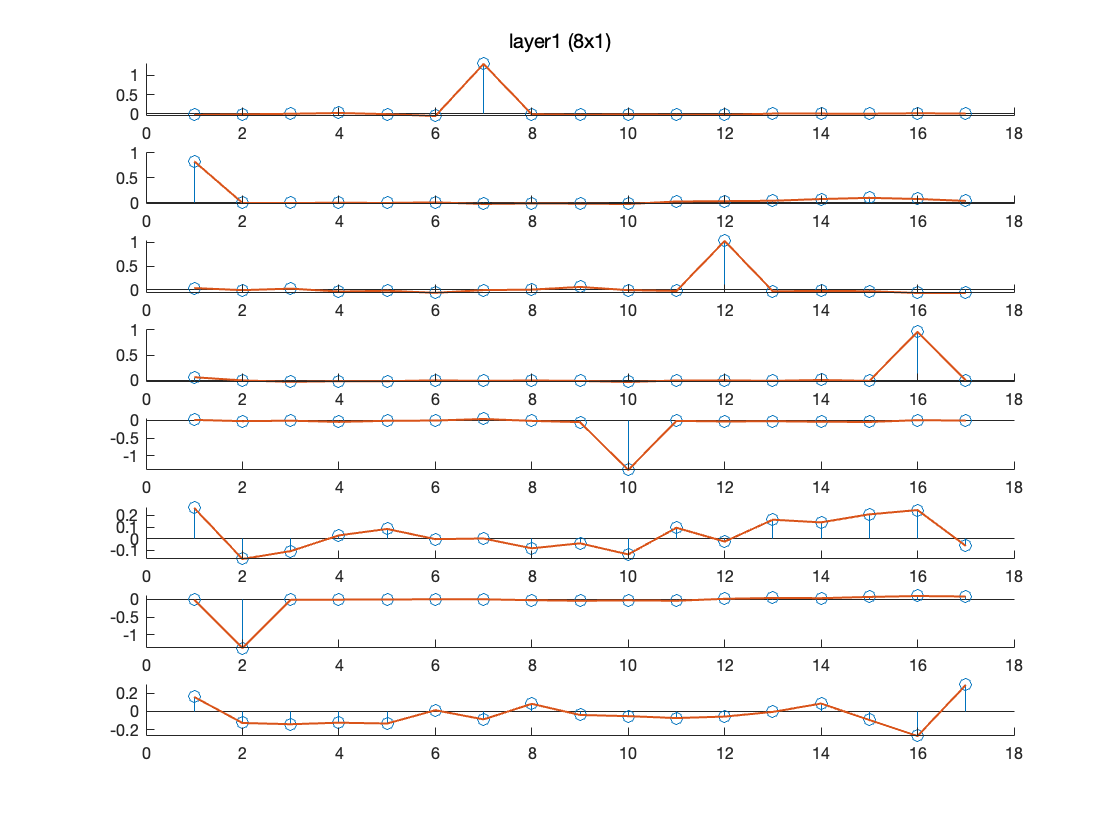

%% Plot the previous training CNN.

set_plot_defaults('on')
load('denoiser_sparse.mat');


h1{1} = double(conv1);
h1{2} = double(conv2);
h1{3} = reshape(double(conv3),[8,1,17]);

figure(1)
[r,c,~] = size(h1{1});
for i=1:1:r
    for j=1:1:c
    subplot(r,c,c*i-(c-j))
    stem(flip(squeeze(h1{1}(i,j,:))))
    hold on
    plot(flip(squeeze(h1{1}(i,j,:))))
    hold off
    box off
    end
end
sgtitle('layer1 (8x1)', 'FontSize', 10);

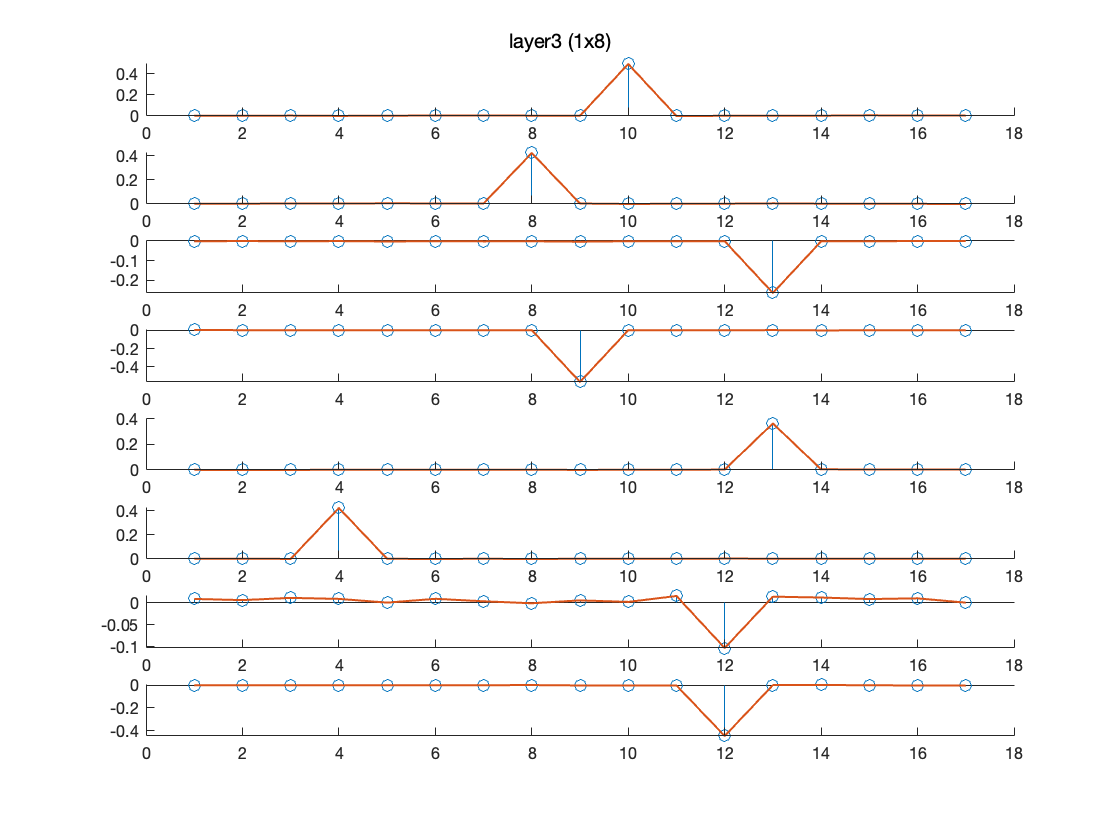


% set(gcf, 'PaperPosition', [1 1 7 15])

% print -depsc figures/previous_layer1

figure(2)
[r,c,~] = size(h1{3});
for i=1:1:r
    for j=1:1:c
    subplot(r,c,c*i-(c-j))
    stem(flip(squeeze(h1{3}(i,j,:))))
    hold on
    plot(flip(squeeze(h1{3}(i,j,:))))
    hold off
    box off
    end
end
sgtitle('layer3 (1x8)', 'FontSize', 10);


% set(gcf, 'PaperPosition', [1 1 7 15])

% print -depsc figures/previous_layer3

set_plot_defaults('off')



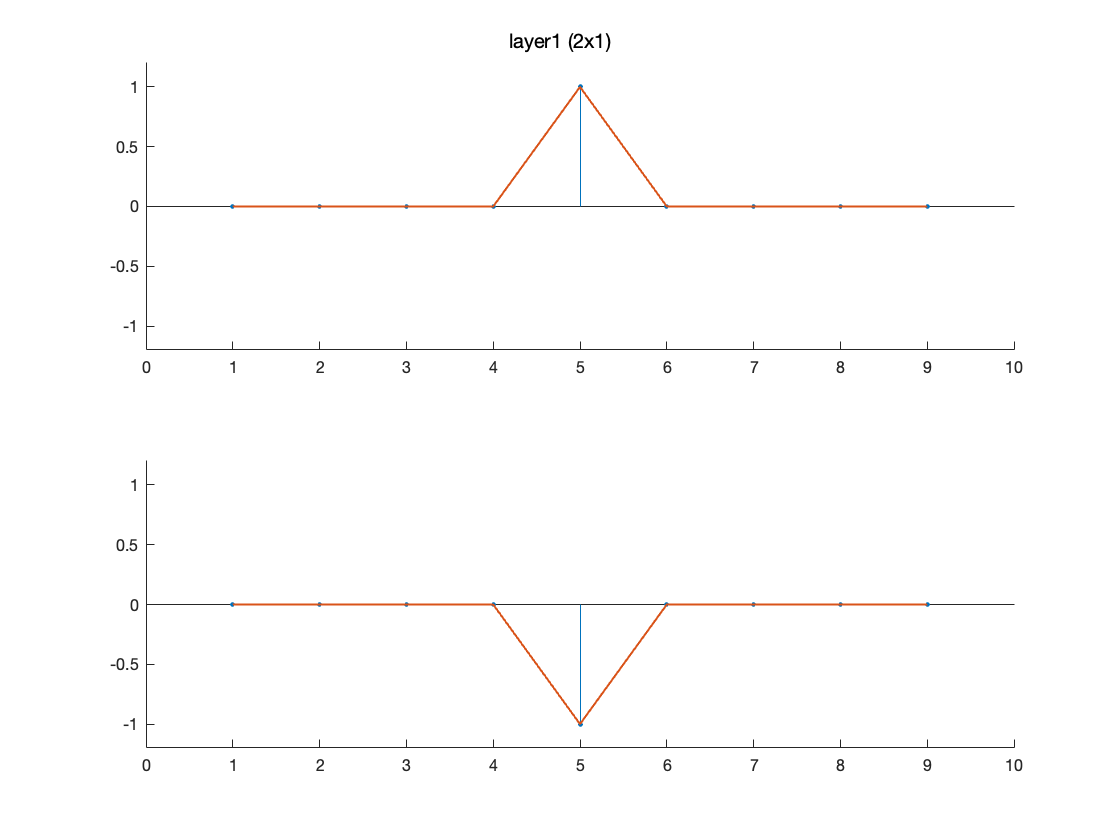

%% Plot the previous training CNN.


load('remove_13_retrained.mat');
h1{1} = double(conv1);
h1{2} = double(conv2);
h1{3} = double(conv3);

set_plot_defaults('on')
figure(3)
[r,c,~] = size(h1{1});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(h1{1}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(h1{1}(i,j,:))))
        hold off
        xlim([0,10])
        ylim([-1.2,1.2])
        box off
    end
end
sgtitle('layer1 (2x1)', 'FontSize', 10);

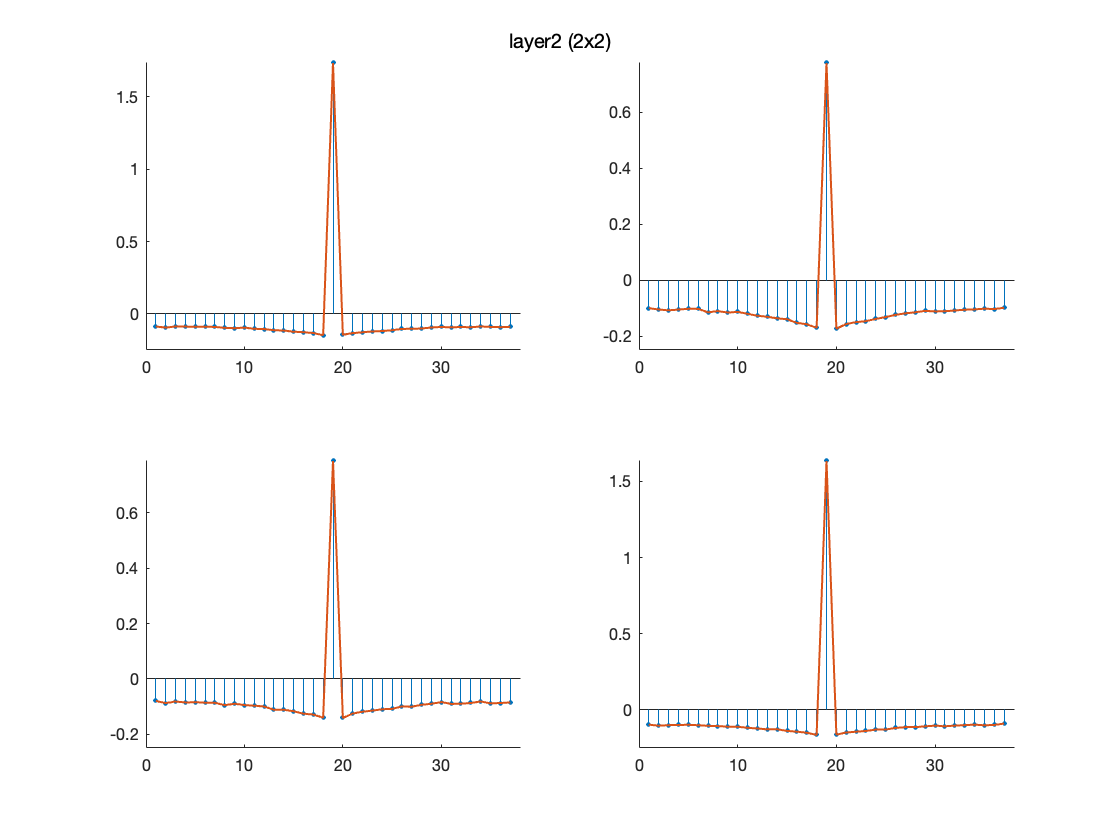


% set(gcf, 'PaperPosition', [1 1 3 6])

% print -depsc figures/layer1_train

figure(4)
[r,c,~] = size(h1{2});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(h1{2}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(h1{2}(i,j,:))))
        hold off
        xlim([0,38])
        ylim([-0.25,inf])
        box off
    end
end
sgtitle('layer2 (2x2)', 'FontSize', 10);

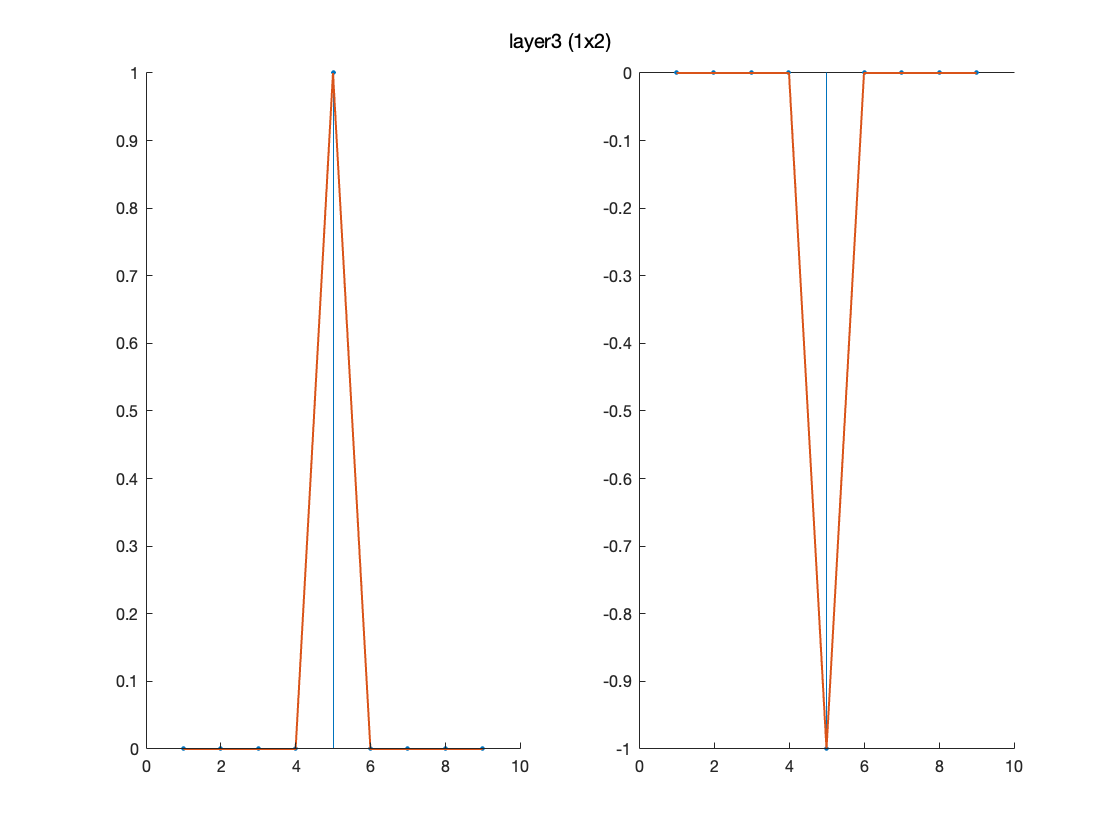


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer2_train

figure(5)
[r,c,~] = size(h1{3});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(h1{3}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(h1{3}(i,j,:))))
        hold off
        box off
    end
end
sgtitle('layer3 (1x2)', 'FontSize', 10);


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer3_train

set_plot_defaults('off')


%% 

% clc
clear
% close all

N = 500;
K = 50;
sigma = 1;
groundtruth = zeros(1, N);
index_random = randperm(N);
index = index_random(1:K);
groundtruth(index) = 10*2*(rand(1,K) - 0.5);
noise = sigma * randn(1,N);
input = groundtruth + noise;


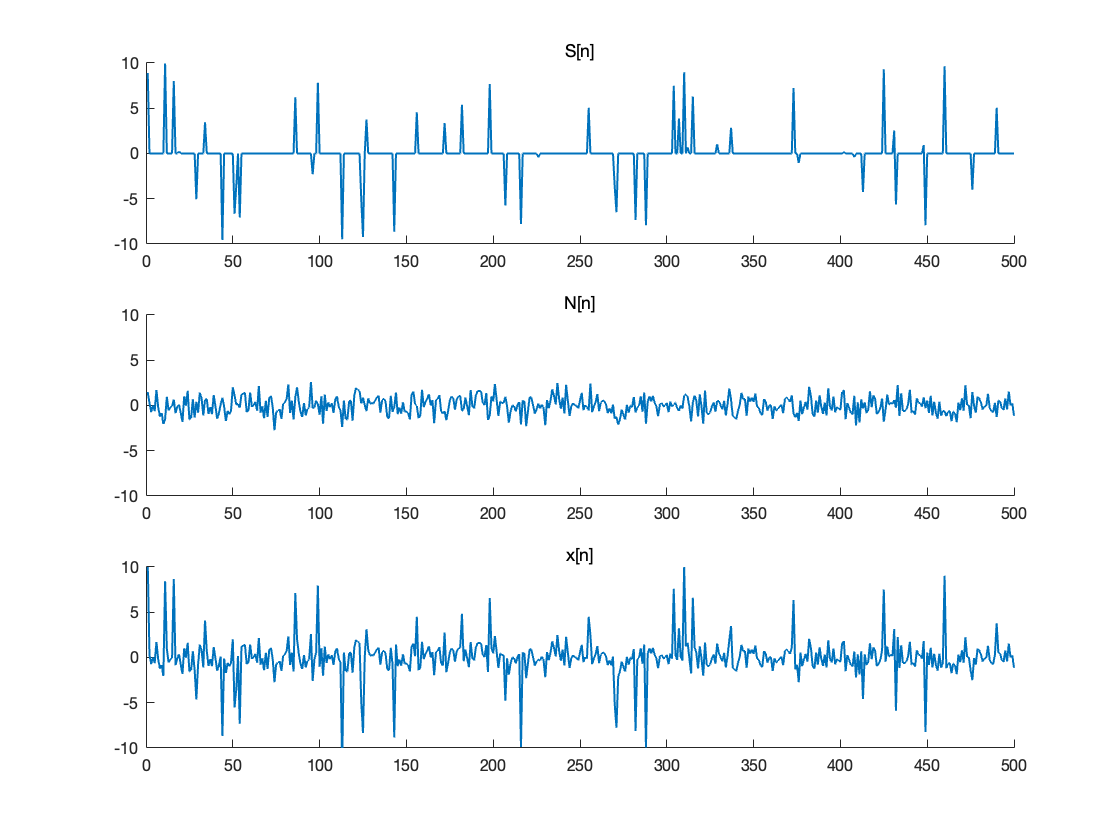

%% Plot the components of the input signal.

set_plot_defaults('on')

figure(6)

subplot(3,1,1)
plot(1:N, groundtruth)
title('S[n]')
ylim([-10 10])

box off

subplot(3,1,2)
plot(1:N, noise)
title('N[n]')
ylim([-10 10])

box off

subplot(3,1,3)
plot(1:N, input)
title('x[n]')
ylim([-10 10])

box off


% set(gcf, 'PaperPosition', [1 1 10 8])

% print -depsc figures/input


set_plot_defaults('off')


%% Create the proposed CNN

threshold1 = 2.4;
threshold2 = 4.8;
rho = 1;                % rho is the ratio between output and input signal.
l = 37;            % l is the length of the filters in the second layer.
training_sigma = 2;     % The standard deviation of the Gaussian noise in the training data is between 0 and training_sigma.
training_num = 60000;   % training_num is the number of the training signals.
training_type = 2;      % 1 means Uniform and 2 means Gaussian.
istrain_flag = false;   % istrain_flag can determine if training a new CNN or directly using the trained parameters.
h1 = create_denoiser(l,rho,threshold1,threshold2,training_type,istrain_flag);


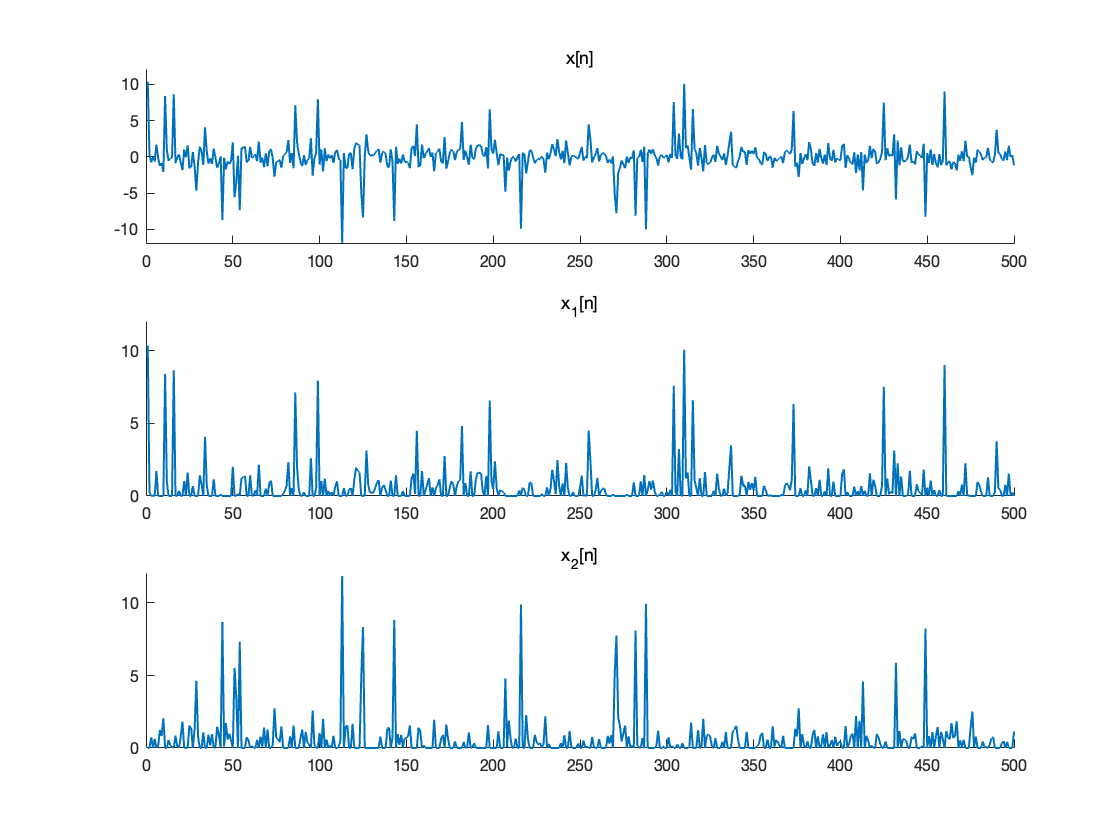

%% Plot the output of each layer

set_plot_defaults('on')

figure(7)
l1 = layer(input, h1{1});
subplot(3,1,1)
plot(1:N,input)
title('x[n]')
ylim([-12,12])
xlim([0,500])
box off
subplot(3,1,2)
plot(1:N,l1(1,:))
title('x_1[n]')
ylim([0,12])
xlim([0,500])
box off
subplot(3,1,3)
plot(1:N,l1(2,:))
title('x_2[n]')
ylim([0,12])
xlim([0,500])
box off

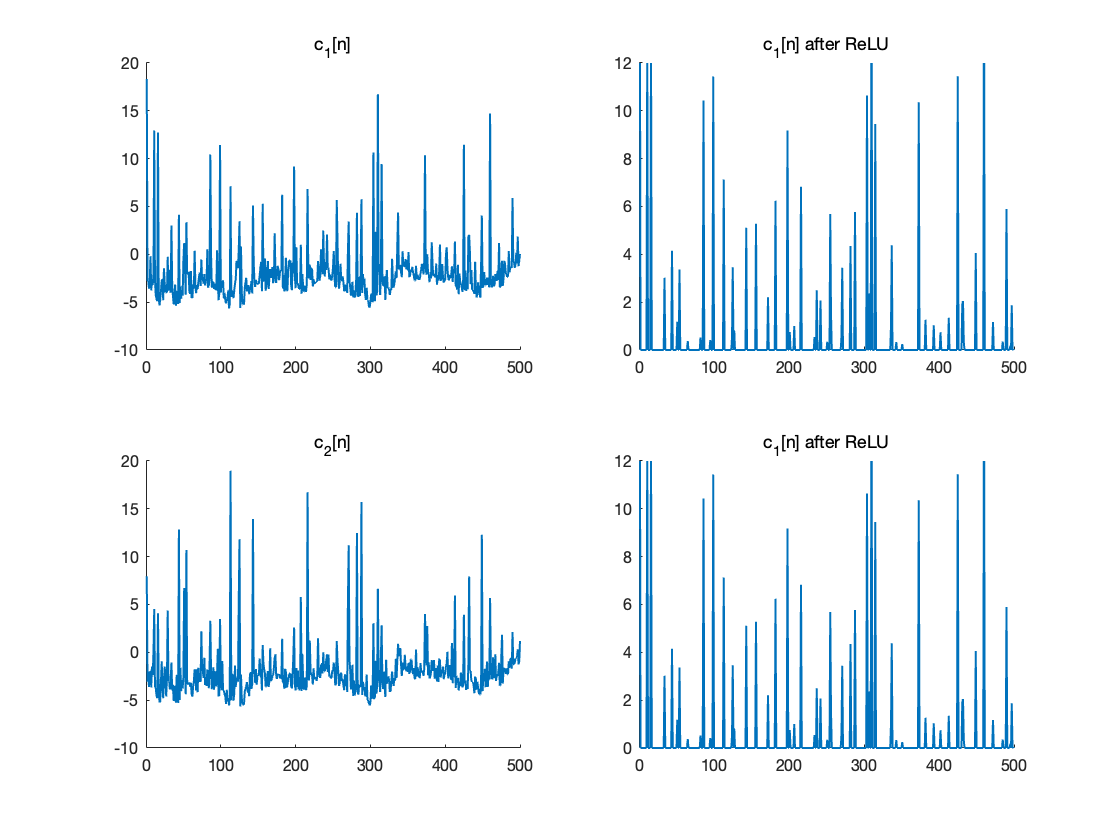

% set(gcf, 'PaperPosition', [1 1 8 9])

% print -depsc figures/l1

figure(8)
l2_NR = conv1d(l1,h1{2});
l2 = ReLU(l2_NR);
subplot(2,2,1)
plot(1:N,l2_NR(1,:))
title('c_1[n]')
ylim([-10,20])
xlim([0,500])
box off
subplot(2,2,3)
plot(1:N,l2_NR(2,:))
title('c_2[n]')
ylim([-10,20])
xlim([0,500])
box off
subplot(2,2,2)
plot(1:N,l2(1,:))
title('c_1[n] after ReLU')
ylim([0,12])
xlim([0,500])
box off
subplot(2,2,4)
plot(1:N,l2(1,:))
title('c_1[n] after ReLU')
ylim([0,12])
xlim([0,500])
box off

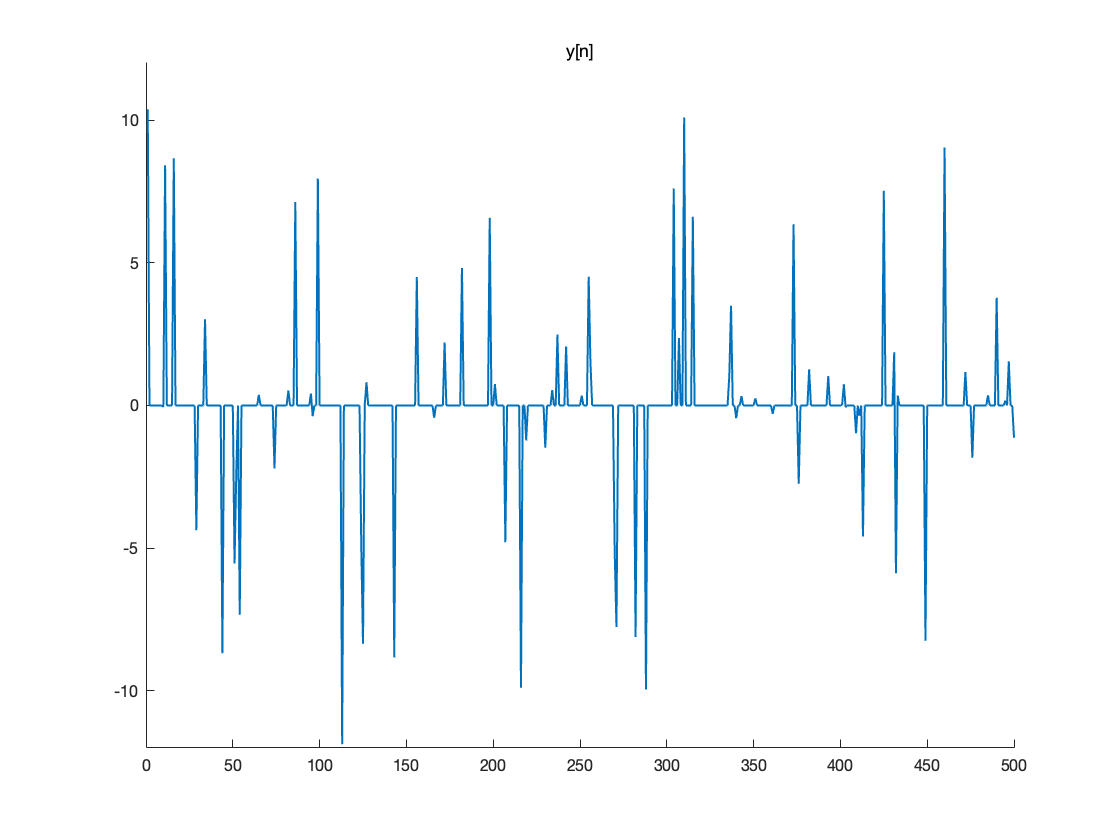

% set(gcf, 'PaperPosition', [1 1 10 6])

% print -depsc figures/l2

figure(9)
l3 = conv1d(l2,h1{3});
plot(1:N,l3)
title('y[n]')
ylim([-12,12])
xlim([0,500])
box off
title('y[n]')

% set(gcf, 'PaperPosition', [1 1 8 3])

% print -depsc figures/l3

set_plot_defaults('off')


%% Plot the structure of the proposed CNN

set_plot_defaults('on')
figure(10)
[r,c,~] = size(h1{1});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(h1{1}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(h1{1}(i,j,:))))
        hold off
        xlim([0,10])
        ylim([-1.2,1.2])
        box off
    end
end
sgtitle('layer1 (2x1)', 'FontSize', 10);

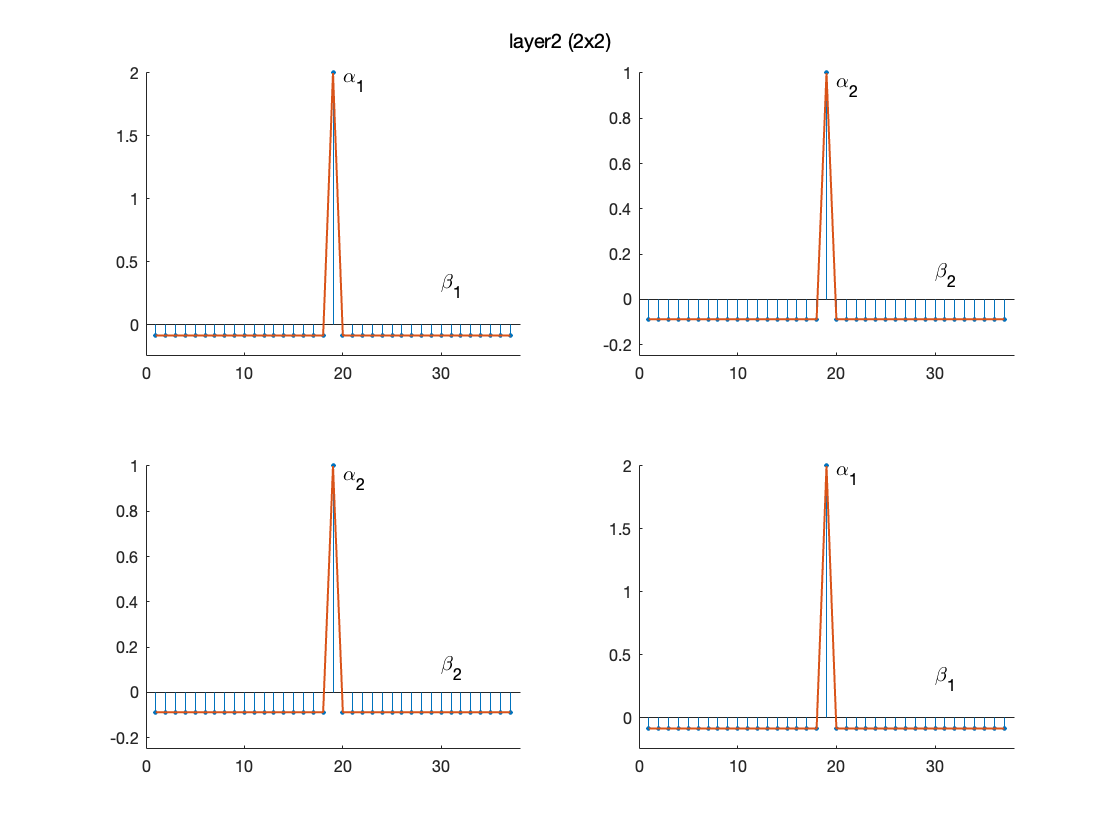


% set(gcf, 'PaperPosition', [1 1 3 6])

% print -depsc figures/layer1

figure(11)
title('Layer 2')
[r,c,~] = size(h1{2});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(h1{2}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(h1{2}(i,j,:))))
        hold on
        plot(19,h1{2}(i,j,19), 'MarkerSize', 10)
        hold on
        if i == j
            text(20,h1{2}(i,j,19)-0.05, '\alpha_1')
            text(30,h1{2}(i,j,8)+0.4, '\beta_1')
        else
            text(20,h1{2}(i,j,19)-0.05, '\alpha_2')
            text(30,h1{2}(i,j,8)+0.2, '\beta_2')
        end
        plot(30,h1{2}(i,j,8), 'MarkerSize', 10)
        hold off
        xlim([0,38])
        ylim([-0.25,inf])
        box off
    end
end
sgtitle('layer2 (2x2)', 'FontSize', 10);


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer2

figure(12)
title('Layer 3')
[r,c,~] = size(h1{3});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(h1{3}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(h1{3}(i,j,:))))
        hold off
        box off
    end
end
sgtitle('layer3 (1x2)', 'FontSize', 10);


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer3

set_plot_defaults('off')


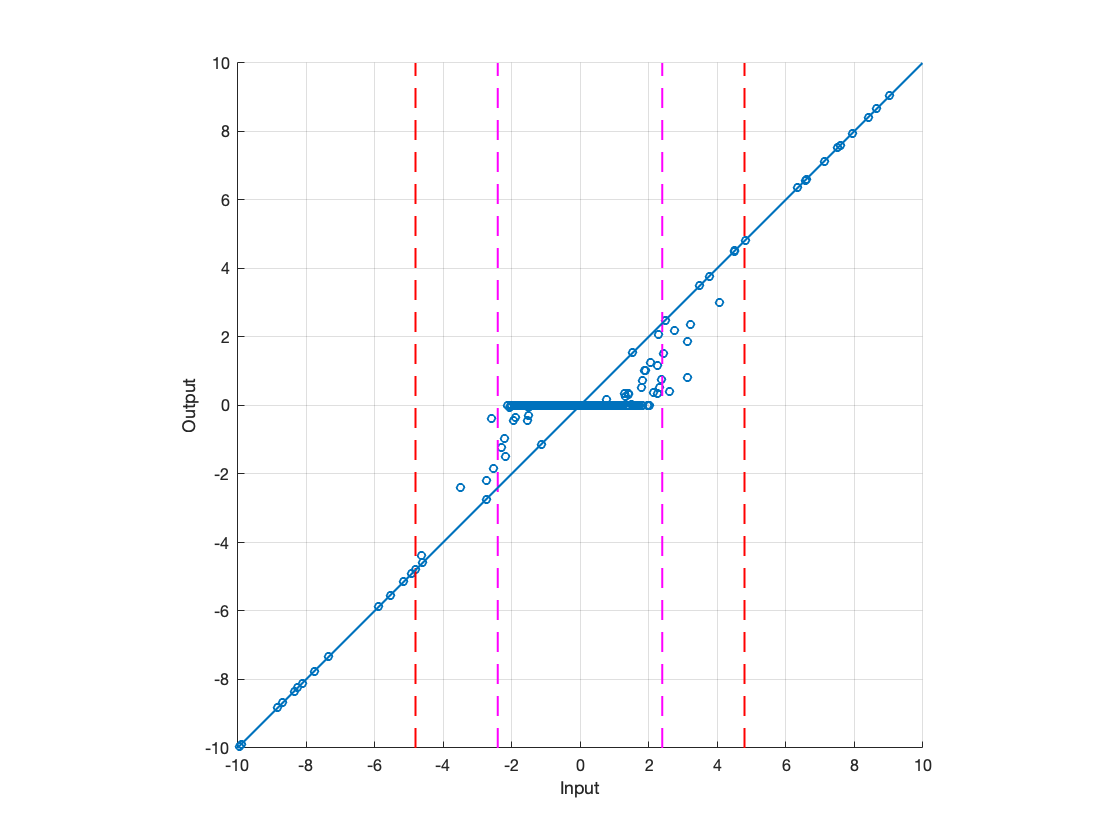

%% Plot the output signal v.s. input signal and display the thresholds.

set_plot_defaults('on')

output = CNN(input,h1);

figure(13)
plot(input, output, 'o', 'MarkerSize', 4)
hold on;
line([threshold1 threshold1], [-10 10],'Color','magenta','LineStyle','--')
line([threshold2 threshold2], [-10 10],'Color','red','LineStyle','--')
line([-threshold1 -threshold1], [-10 10],'Color','magenta','LineStyle','--')
line([-threshold2 -threshold2], [-10 10],'Color','red','LineStyle','--')
xlabel('Input')
ylabel('Output')
grid
axis equal square
line([-10 10], [-10 10])
axis([-10,10,-10,10])
box off


% set(gcf, 'PaperPosition', [1 1 9 9])

% print -depsc figures/threshold

set_plot_defaults('off')


%% Create the proposed CNN

threshold1 = 2.61;
threshold2 = 5.26;
rho = 1;                % rho is the ratio between output and input signal.
l = 37;                 % l is the length of the filters in the second layer.
training_sigma = 2;     % The standard deviation of the Gaussian noise in the training data is between 0 and training_sigma.
training_num = 60000;   % training_num is the number of the training signals.
training_type = 1;      % 1 means Uniform and 2 means Gaussian.
istrain_flag = false;   % istrain_flag can determine if training a new CNN or directly using the trained parameters.
h1 = create_denoiser(l,rho,threshold1,threshold2,training_type,istrain_flag);


N = 500;
K = 25;
sigma = 0.5;
groundtruth = zeros(1, N);
index_random = randperm(N);
index = index_random(1:K);
groundtruth(index) = 10*2*(rand(1,K) - 0.5);
noise = sigma * randn(1,N);
input = groundtruth + noise;


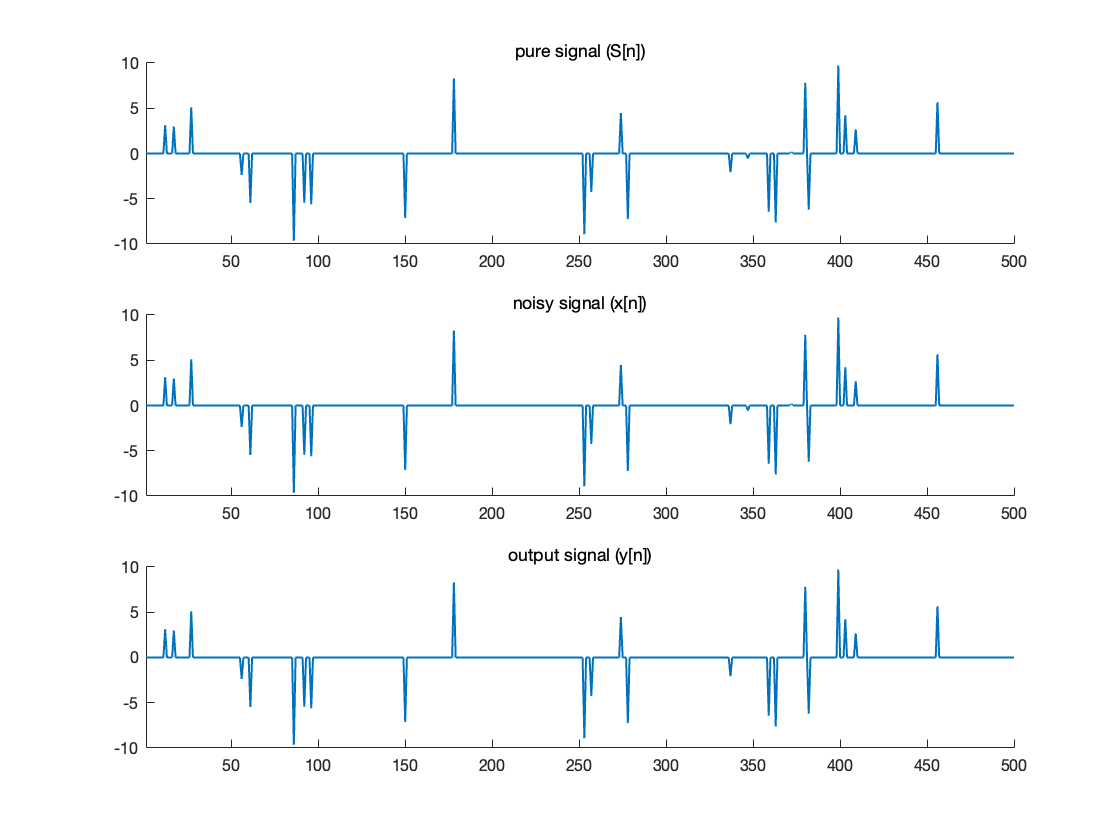

%% Display groundtruth, input signal and output signal. Plot input signal v.s. output signal in two forms. Pure signal case.

set_plot_defaults('on')

figure(14)
output = CNN(groundtruth, h1);
subplot(3,1,1)
plot(groundtruth)
title('pure signal (S[n])');
xlim([1,500])
ylim([-10,10])
box off
subplot(3,1,2)
plot(groundtruth)
title('noisy signal (x[n])');
xlim([1,500])
ylim([-10,10])
box off
subplot(3,1,3)
plot(output)
title('output signal (y[n])');
xlim([1,500])
ylim([-10,10])
box off

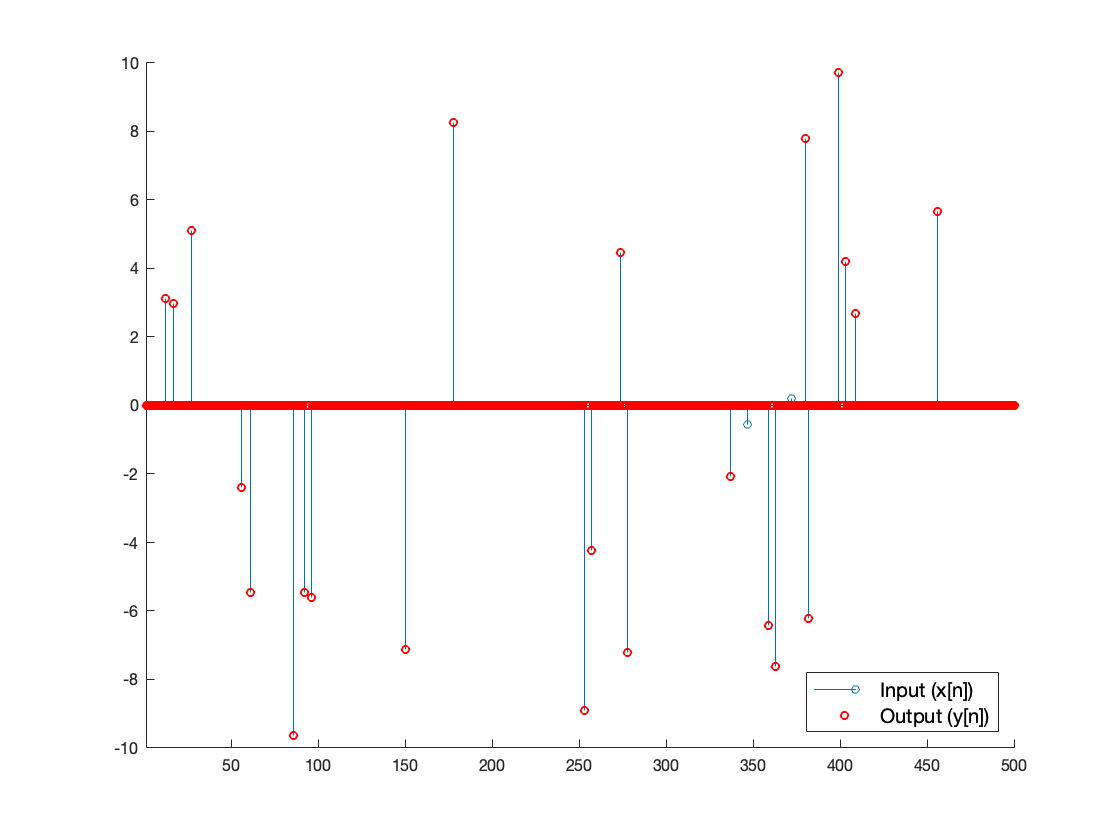


% set(gcf, 'PaperPosition', [1 1 14 8])

% print -depsc figures/pure1

n = 1:N;
figure(15)
stem(n, groundtruth, 'MarkerSize', 4)
hold on
plot(n, output, 'ro', 'MarkerSize', 4)
hold off
legend('Input (x[n])', 'Output (y[n])', 'Location', 'SouthEast', 'FontSize', 10)
xlim([1,500])
ylim([-10,10])
% title('Input v.s. output')
box off


% set(gcf, 'PaperPosition', [1 1 14 8])

% print -depsc figures/pure2

loss = mean((output - groundtruth).^2)

loss = 7.2311e-04

SNR = 10*log10(mean(groundtruth.^2)/loss)

SNR = 33.8549

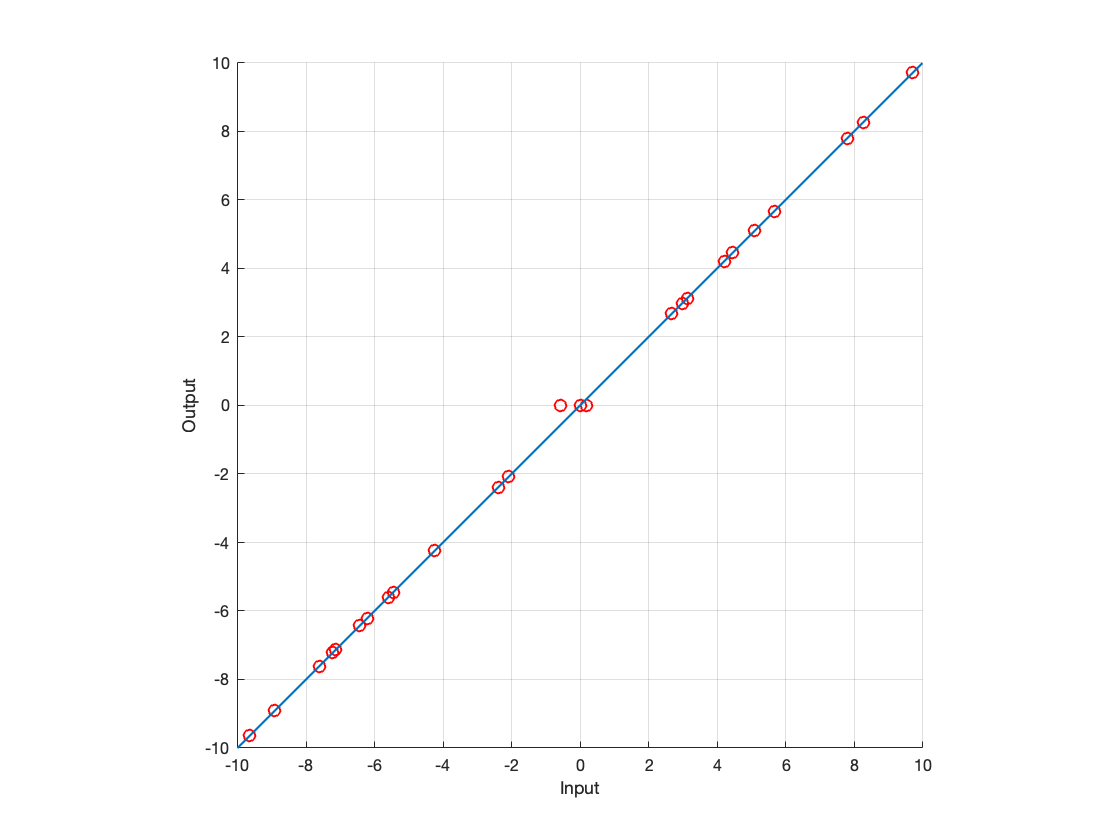


figure(16)
plot(groundtruth, output, 'ro')
hold on
xlabel('Input')
ylabel('Output')
grid
axis equal square
line([-10 10], [-10 10])
hold off
% title('Input v.s. output')
box off


% set(gcf, 'PaperPosition', [1 1 10 10])

% print -depsc figures/pure3

set_plot_defaults('off')


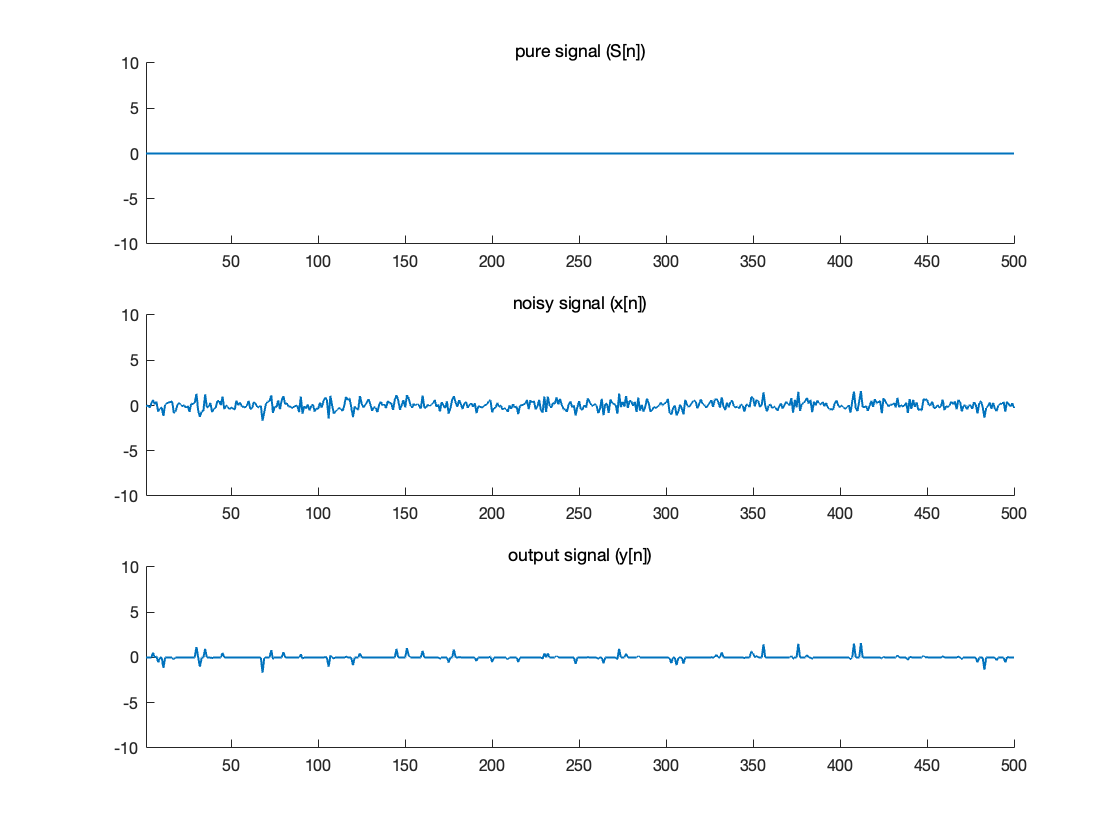

%% Display groundtruth, input signal and output signal. Plot input signal v.s. output signal in two forms. Pure noise case.

set_plot_defaults('on')

figure(17)
output = CNN(noise, h1);
subplot(3,1,1)
plot(zeros(1,N))
title('pure signal (S[n])');
xlim([1,500])
ylim([-10,10])
box off
subplot(3,1,2)
plot(noise)
title('noisy signal (x[n])');
xlim([1,500])
ylim([-10,10])
box off
subplot(3,1,3)
plot(output)
title('output signal (y[n])');
xlim([1,500])
ylim([-10,10])
box off

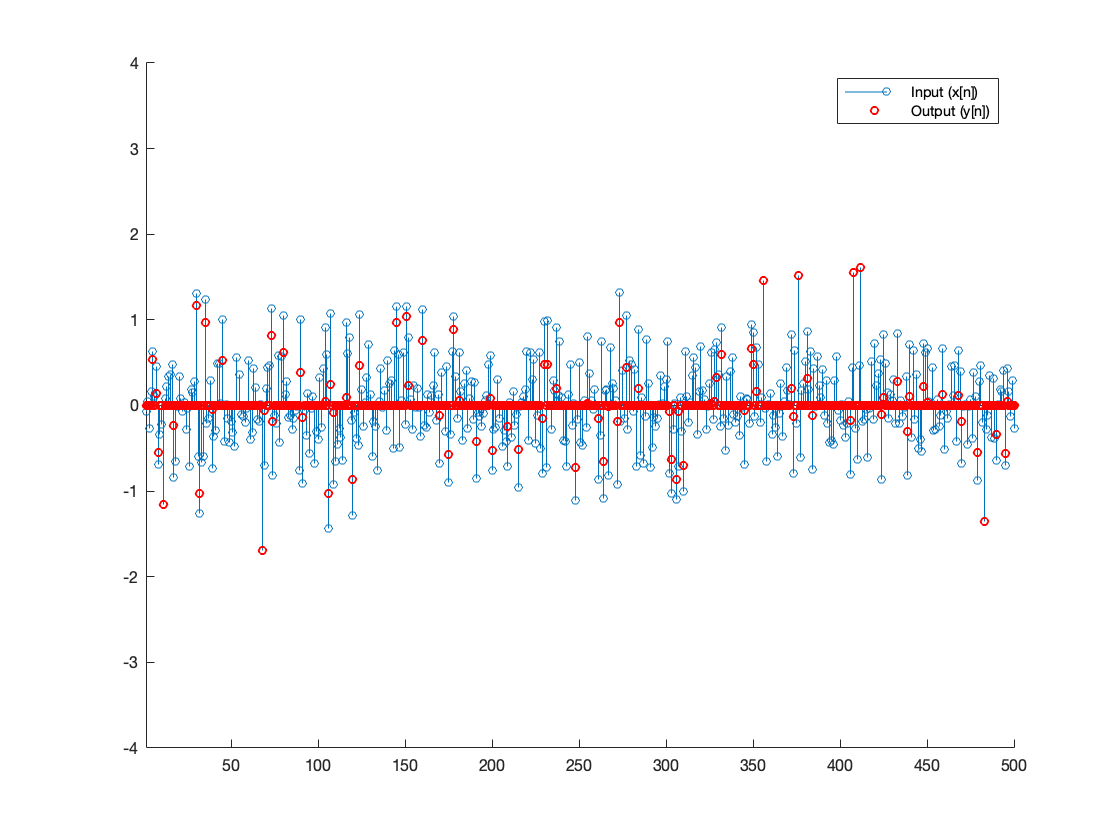


% set(gcf, 'PaperPosition', [1 1 14 8])

% print -depsc figures/noise1

n = 1:N;
figure(18)
stem(n, noise, 'MarkerSize', 4)
hold on
plot(n, output, 'ro', 'MarkerSize', 4)
hold off
legend('Input (x[n])', 'Output (y[n])')
xlim([1,500])
ylim([-4,4])
% title('Input v.s. output')
box off


% set(gcf, 'PaperPosition', [1 1 14 8])

% print -depsc figures/noise2

loss = mean((output - 0).^2)

loss = 0.0689

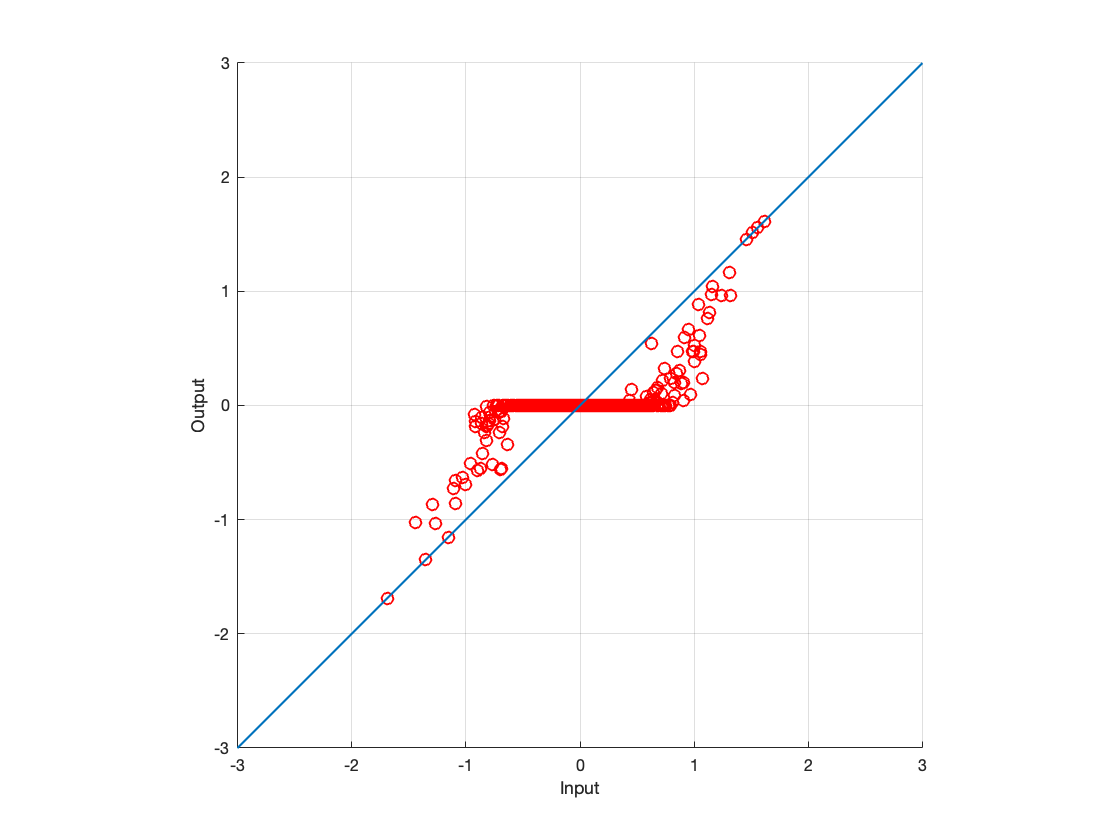

% mean(noise.^2)
% SNR = 10*log10(mean(groundtruth.^2)/loss)

figure(19)
plot(noise, output, 'ro')
hold on
xlabel('Input')
ylabel('Output')
grid
axis equal square
line([-3 3], [-3 3])
hold off
% title('Input v.s. output')
box off


% set(gcf, 'PaperPosition', [1 1 9 9])

% print -depsc figures/noise3

set_plot_defaults('off')



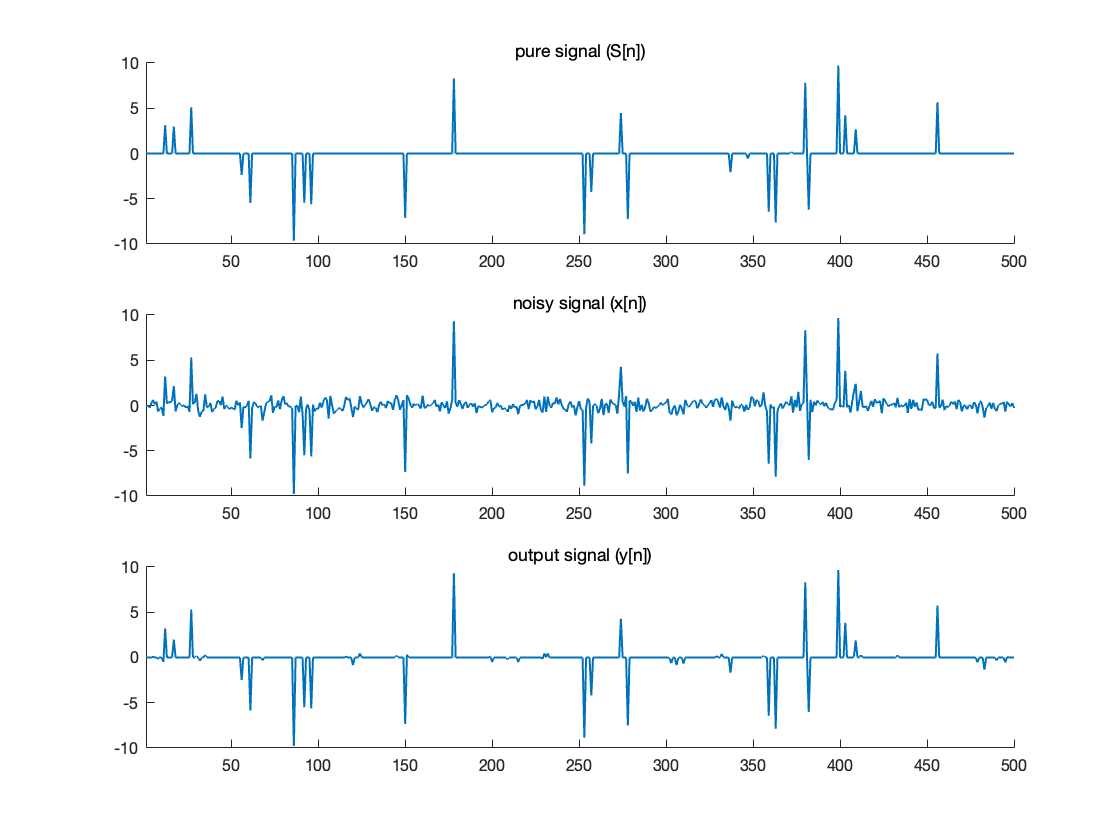

%% Display groundtruth, input signal and output signal. Plot input signal v.s. output signal in two forms. Noisy signal case.

set_plot_defaults('on')

figure(20)
output = CNN(input, h1);
subplot(3,1,1)
plot(groundtruth)
title('pure signal (S[n])');
xlim([1,500])
ylim([-10,10])
box off
subplot(3,1,2)
plot(input)
title('noisy signal (x[n])');
xlim([1,500])
ylim([-10,10])
box off
subplot(3,1,3)
plot(output)
title('output signal (y[n])');
xlim([1,500])
ylim([-10,10])
box off

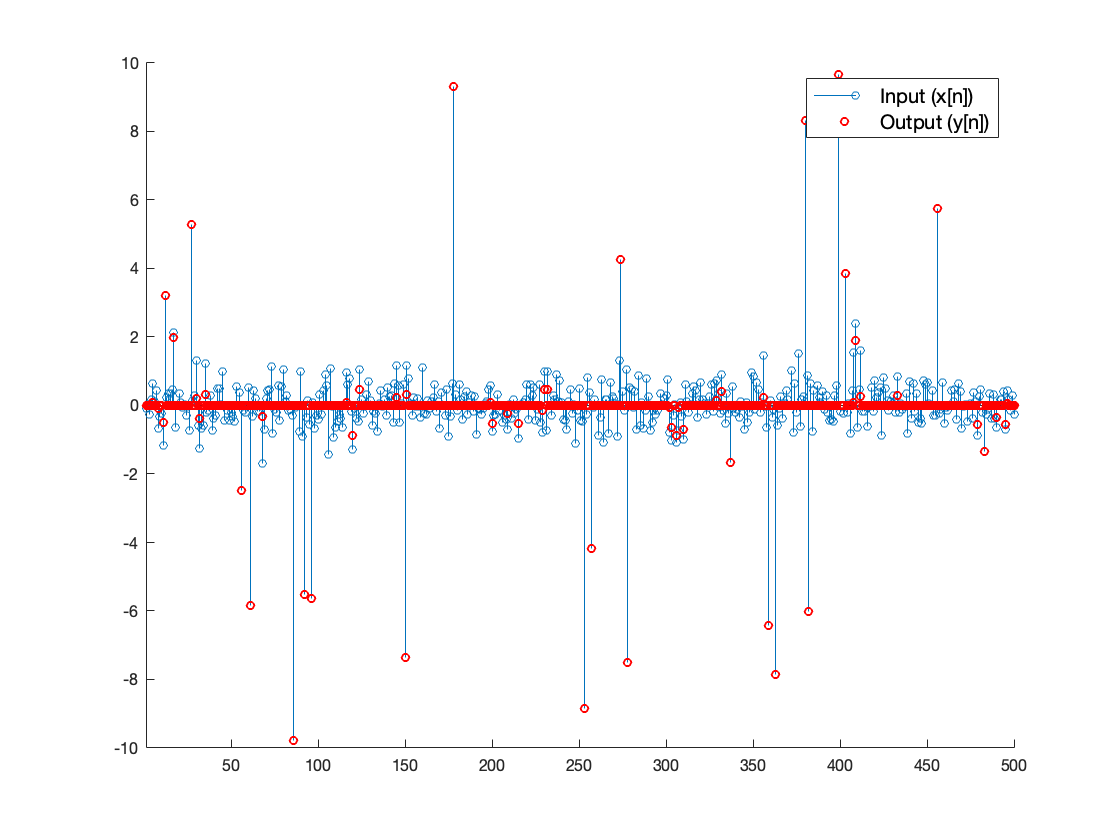


% set(gcf, 'PaperPosition', [1 1 14 8])

% print -depsc figures/noisy1

n = 1:N;
figure(21)
stem(n, input, 'MarkerSize', 4)
hold on
plot(n, output, 'ro', 'MarkerSize', 4)
hold off
legend('Input (x[n])', 'Output (y[n])', 'FontSize', 10)
xlim([1,500])
ylim([-10,10])
% title('Input v.s. output')
box off


% set(gcf, 'PaperPosition', [1 1 14 8])

% print -depsc figures/noisy2


loss = mean((output - groundtruth).^2)

loss = 0.0232

output_SNR = 10*log10(mean(groundtruth.^2)/loss)

output_SNR = 18.7927

input_SNR = 10*log10(mean(groundtruth.^2)/mean((input - groundtruth).^2))

input_SNR = 8.2861

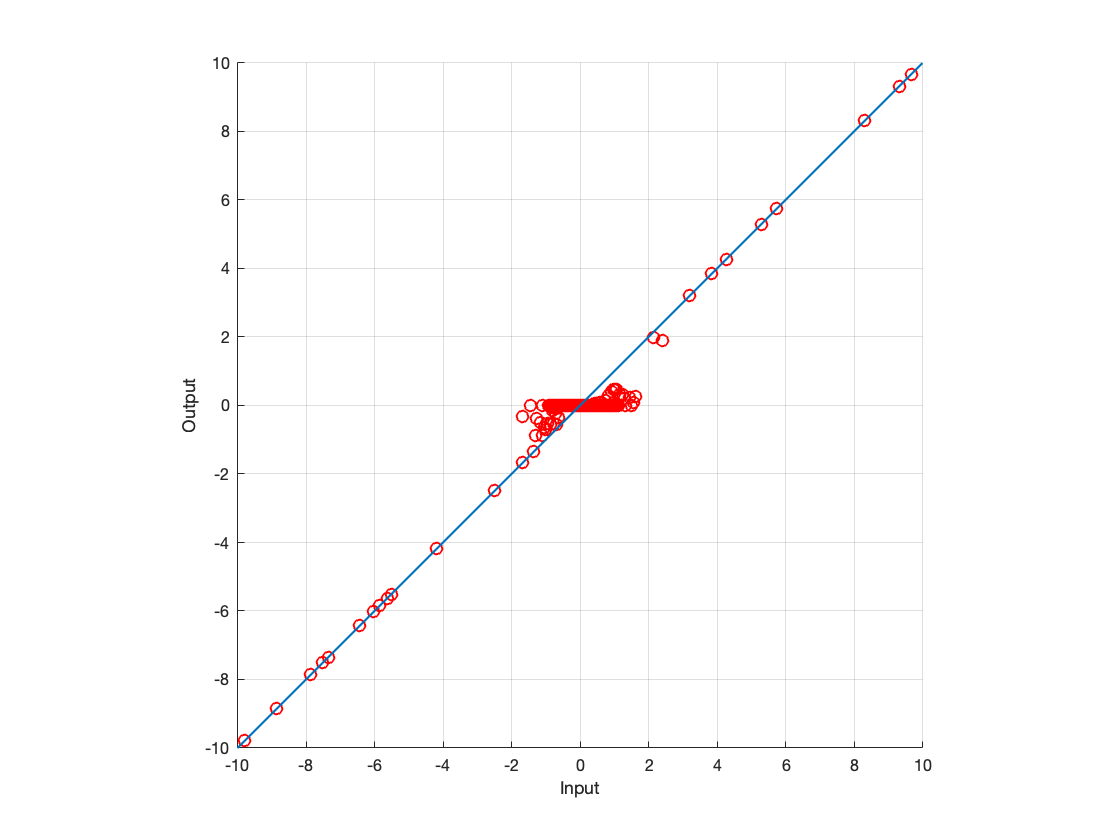


figure(22)
plot(input, output, 'ro')
hold on
xlabel('Input')
ylabel('Output')
grid
axis equal square
line([-10 10], [-10 10])
hold off
% title('Input v.s. output')
box off


% set(gcf, 'PaperPosition', [1 1 9 9])

% print -depsc figures/noisy3

set_plot_defaults('off')


%% Create input signal (noisy signal) and ground truth (pure signal) for the performance part.

% N is the total length of the pure sparse signal.
% K is the number of non-zeros in the pure sparse signal.
% As a result, 1-K/N determines the sparsity of the pure signal.

N = 500;
num = 1000;
sigma_set = logspace(log10(0.1), log10(2), 20);
% sigma_set = 0.1:0.1:2;

MSE_output_ave = zeros(3,length(sigma_set));
MSE_input_ave = zeros(3,length(sigma_set));
SNR_output_ave = zeros(3,length(sigma_set));
SNR_input_ave = zeros(3,length(sigma_set));

for m = 1:1:3
    K = 25 * m;
    for i = 1:1:length(sigma_set)

        sigma = sigma_set(i);
        SNR_output = zeros(1,num);
        SNR_input = zeros(1,num);
        MSE_output = zeros(1,num);
        MSE_input = zeros(1,num);
        for j = 1:1:num

            groundtruth = zeros(1, N);
            index_random = randperm(N);
            index = index_random(1:K);
            groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
    %         groundtruth(index)  = 10*randn(1,K);
            input_noise = sigma*randn(1,N);
            input = groundtruth + input_noise;
            output = CNN(input, h1);
            noise = output - groundtruth;
            MSE_output(j) = mean(noise.^2);
            MSE_input(j) = mean(input_noise.^2);
            SNR_output(j) = 10*log10(mean(groundtruth.^2)/MSE_output(j));
            SNR_input(j) = 10*log10(mean(groundtruth.^2)/MSE_input(j));

        end
        SNR_output_ave(m,i) = mean(SNR_output);
        SNR_input_ave(m,i) = mean(SNR_input);
%         MSE_output_ave(m,i) = mean(MSE_output);
%         MSE_input_ave(m,i) = mean(MSE_input);
        MSE_output_ave(m,i) = sqrt(mean(MSE_output));
        MSE_input_ave(m,i) = sqrt(mean(MSE_input));

    end
end


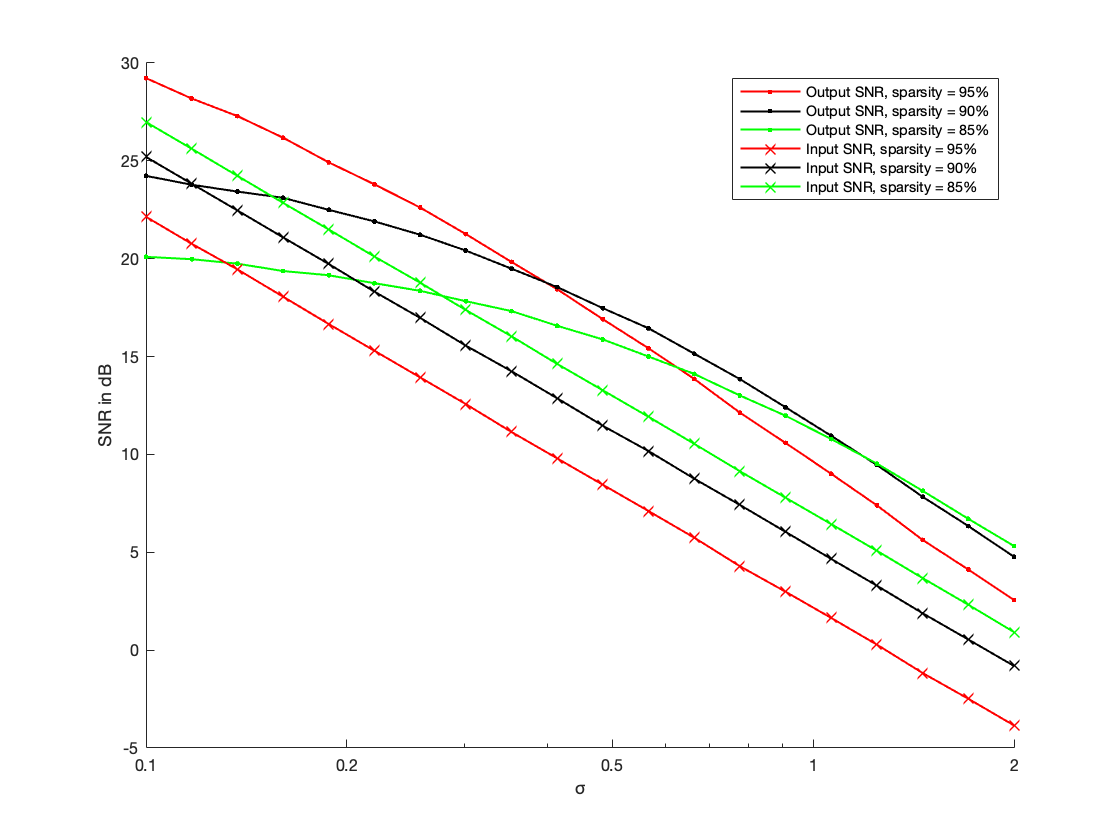

%% Plot the performance v.s. sparsity and noise level.

set_plot_defaults('on')

figure(23)
semilogx(sigma_set,SNR_output_ave(1,:),'r.-',sigma_set,SNR_output_ave(2,:),'k.-',sigma_set,SNR_output_ave(3,:),'g.-')
hold on
semilogx(sigma_set,SNR_input_ave(1,:),'rx-',sigma_set,SNR_input_ave(2,:),'kx-',sigma_set,SNR_input_ave(3,:),'gx-')
hold off
legend('Output SNR, sparsity = 95%','Output SNR, sparsity = 90%','Output SNR, sparsity = 85%', ...
       'Input SNR, sparsity = 95%', 'Input SNR, sparsity = 90%', 'Input SNR, sparsity = 85%')
xlabel('σ')
ylabel('SNR in dB')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_set) max(sigma_set)])
box off

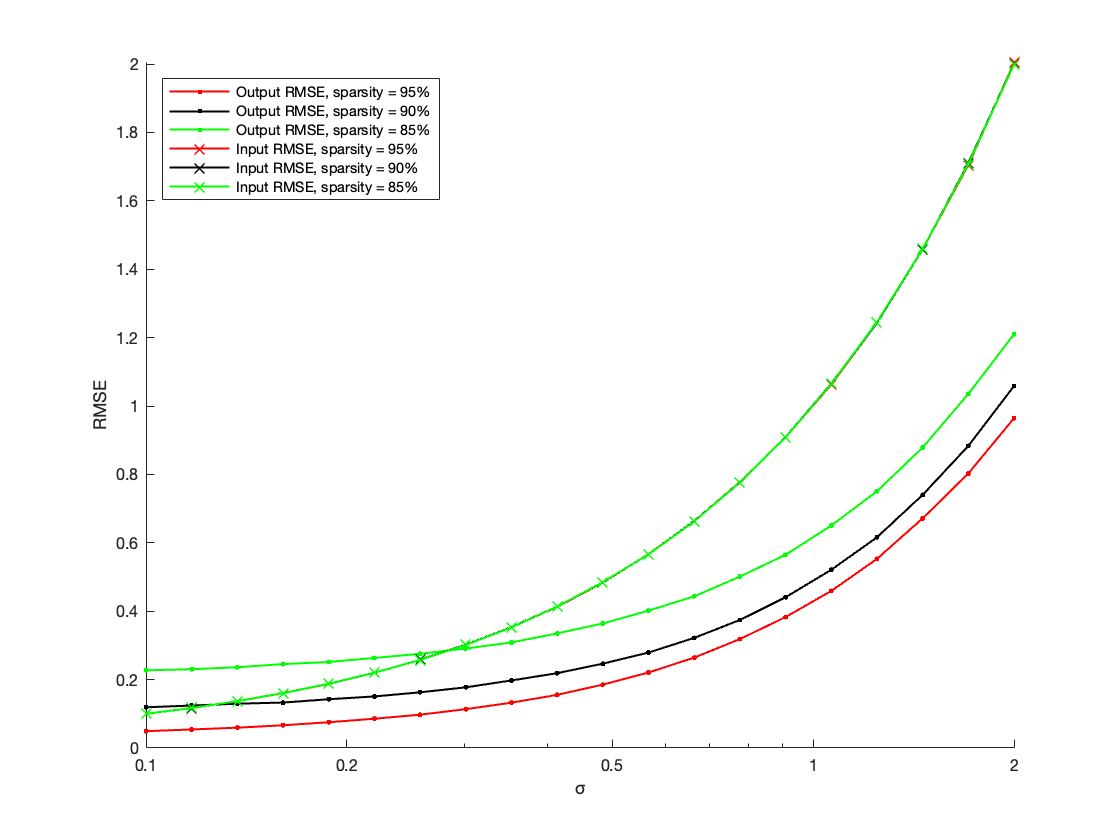


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/SNR_sparsity

figure(24)
semilogx(sigma_set,MSE_output_ave(1,:),'r.-',sigma_set,MSE_output_ave(2,:),'k.-',sigma_set,MSE_output_ave(3,:),'g.-')
hold on
semilogx(sigma_set,MSE_input_ave(1,:),'rx-',sigma_set,MSE_input_ave(2,:),'kx-',sigma_set,MSE_input_ave(3,:),'gx-')
hold off
legend('Output RMSE, sparsity = 95%','Output RMSE, sparsity = 90%','Output RMSE, sparsity = 85%', ...
       'Input RMSE, sparsity = 95%', 'Input RMSE, sparsity = 90%', 'Input RMSE, sparsity = 85%', 'Location','NorthWest')
xlabel('σ')
ylabel('RMSE')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_set) max(sigma_set)])
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/MSE_sparsity

set_plot_defaults('off')


%% Create the performance form for multiple sparsities


SNR_input_ave = zeros(1,5);
SNR_output_ave = zeros(1,5);
MSE_input_ave = zeros(1,5);
MSE_output_ave = zeros(1,5);

N = 500;
num = 10000;

for i = 1:1:5
    
    sparsity = 2.5 * (i + 1);
    K = round(500 * sparsity/100);
    SNR_output = zeros(1,num);
    SNR_input = zeros(1,num);
    MSE_output = zeros(1,num);
    MSE_input = zeros(1,num);
    
    for j = 1:1:num
        
        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
        sigma = 2 * rand();
        input_noise = sigma*randn(1,N);
        input = groundtruth + input_noise;
        output = CNN(input, h1);
        noise = output - groundtruth;
        MSE_output(j) = mean(noise.^2);
        MSE_input(j) = mean(input_noise.^2);
        SNR_output(j) = 10*log10(mean(groundtruth.^2)/MSE_output(j));
        SNR_input(j) = 10*log10(mean(groundtruth.^2)/MSE_input(j));
        
    end
    SNR_input_ave(i) = mean(SNR_input);
    SNR_output_ave(i) = mean(SNR_output);
    MSE_input_ave(i) = mean(MSE_input);
    MSE_output_ave(i) = mean(MSE_output);
    
end

SNR_input_ave

SNR_input_ave =     4.8082    6.5336    7.9970    8.7514    9.5033


SNR_output_ave

SNR_output_ave =    12.0075   12.7675   12.9235   12.3450   11.8883


MSE_input_ave

MSE_input_ave =     1.3255    1.3341    1.3143    1.3607    1.3527


MSE_output_ave

MSE_output_ave =     0.2773    0.3042    0.3438    0.4289    0.5134


%% Create the performance form for multiple noise levels

SNR_input_ave = zeros(1,8);
SNR_output_ave = zeros(1,8);
MSE_input_ave = zeros(1,8);
MSE_output_ave = zeros(1,8);



for i = 1:1:8
    
    sigma = 0.25 * i;
    SNR_output = zeros(1,num);
    SNR_input = zeros(1,num);
    MSE_output = zeros(1,num);
    MSE_input = zeros(1,num);
    for j = 1:1:num
        
        K = ceil(50*rand()+25);
        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
        input_noise = sigma*randn(1,N);
        input = groundtruth + input_noise;
        output = CNN(input, h1);
        noise = output - groundtruth;
        MSE_output(j) = mean(noise.^2);
        MSE_input(j) = mean(input_noise.^2);
        SNR_output(j) = 10*log10(mean(groundtruth.^2)/MSE_output(j));
        SNR_input(j) = 10*log10(mean(groundtruth.^2)/MSE_input(j));
        
    end
    SNR_input_ave(i) = mean(SNR_input);
    SNR_output_ave(i) = mean(SNR_output);
    MSE_input_ave(i) = mean(MSE_input);
    MSE_output_ave(i) = mean(MSE_output);
    
end

SNR_input_ave

SNR_input_ave =    17.0948   11.0749    7.5190    5.0472    3.1186    1.5245    0.1928   -0.9624


SNR_output_ave

SNR_output_ave =    21.1331   16.9353   13.7486   11.2079    9.1184    7.3396    5.8310    4.5180


MSE_input_ave

MSE_input_ave =     0.0625    0.2498    0.5630    0.9996    1.5617    2.2511    3.0616    3.9931


MSE_output_ave

MSE_output_ave =     0.0316    0.0726    0.1429    0.2524    0.4054    0.6062    0.8562    1.1545


%% Compare the proposed CNN with other methods. Create all the methods.

threshold1 = 2.61;
threshold2 = 5.26;
rho = 1;                % rho is the ratio between output and input signal.
l = 37;            % l is the length of the filters in the second layer.
training_sigma = 2;     % The standard deviation of the Gaussian noise in the training data is between 0 and training_sigma.
training_num = 20000;   % training_num is the number of the training signals.
training_type = 1;      % 1 means Uniform and 2 means Gaussian.
istrain_flag = false;   % istrain_flag can determine if training a new CNN or directly using the trained parameters.
h1 = create_denoiser(l,rho,threshold1,threshold2,training_type,istrain_flag);
% h1 = create_denoiser(l,rho,threshold1,threshold2,training_type,istrain_flag,training_num,training_sigma);
% load('CNNs/2hidden_unfix.mat');
% h2{1} = conv1;
% h2{2} = conv2;
% h2{3} = conv3;
% h2{4} = conv4;
load('CNNs/3hidden_unfix.mat');
h3{1} = conv1;
h3{2} = conv2;
h3{3} = conv3;
h3{4} = conv4;
h3{5} = conv5;
% load('CNNs/4kernel_fix.mat');
% h4{1} = conv1;
% h4{2} = conv2;
% h4{3} = conv3;
% h4{4} = conv4;
load('CNNs/8kernel_fix.mat');
h4{1} = conv1;
h4{2} = conv2;
h4{3} = conv3;
h4{4} = conv4;


%% Create input signal (noisy signal) and groundtruth (pure signal).

% N is the total length of the pure sparse signal.
% K is the number of non-zeros in the pure sparse signal.
% As a result, 1-K/N determines the sparsity of the pure signal.

N = 500;
num = 1000;
sigma_set = 0.1:0.1:2;
SNR_1 = zeros(1,length(sigma_set));
MSE_1 = zeros(1,length(sigma_set));
SNR_3 = zeros(1,length(sigma_set));
MSE_3 = zeros(1,length(sigma_set));
SNR_4 = zeros(1,length(sigma_set));
MSE_4 = zeros(1,length(sigma_set));

for i = 1:1:length(sigma_set)
    
    sigma = sigma_set(i);
    SNR_num1 = zeros(1,num);
    MSE_num1 = zeros(1,num);
    SNR_num3 = zeros(1,num);
    MSE_num3 = zeros(1,num);
    SNR_num4 = zeros(1,num);
    MSE_num4 = zeros(1,num);
    for j = 1:1:num
        
        K = ceil(50*rand()+25);
        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
        input = groundtruth + sigma*randn(1,N);
        
        output = CNN(input, h1);
        noise = output - groundtruth;
        MSE_num1(j) = mean(noise.^2);
        SNR_num1(j) = 10*log10(mean(groundtruth.^2)/MSE_num1(j));

        output = CNN(input, h3);
        noise = output - groundtruth;
        MSE_num3(j) = mean(noise.^2);
        SNR_num3(j) = 10*log10(mean(groundtruth.^2)/MSE_num3(j));
        
        
        output = CNN(input, h4);
        noise = output - groundtruth;
        MSE_num4(j) = mean(noise.^2);
        SNR_num4(j) = 10*log10(mean(groundtruth.^2)/MSE_num4(j));
        
        
          
    end
    SNR_1(i) = mean(SNR_num1);
%     MSE_1(i) = mean(MSE_num1);
    MSE_1(i) = sqrt(mean(MSE_num1));
    SNR_3(i) = mean(SNR_num3);
%     MSE_3(i) = mean(MSE_num3);
    MSE_3(i) = sqrt(mean(MSE_num3));
    SNR_4(i) = mean(SNR_num4);
%     MSE_4(i) = mean(MSE_num4);
    MSE_4(i) = sqrt(mean(MSE_num4));
    
end


%% Plot the performance figures of different methods.

K = 50;
ratio = K/N;                          % sparsity level
sigma_x = 10.0;                     % Gaussian standard deviation

% [sigma_w_, SNR_x_hat, SNR_y, MSE_mad] = sparse_denoise_MAD_calculate_SNR(N, ratio, sigma_x);
% MSE_mad = sqrt(MSE_mad);
[sigma_w_, SNR_x_soft, SNR_x_firm, SNR_y, MSE_firm, MSE_soft] = sparse_denoise_MAD_calculate_SNR(N, ratio, sigma_x);

progress = 0.050000
progress = 0.100000
progress = 0.150000
progress = 0.200000
progress = 0.250000
progress = 0.300000
progress = 0.350000
progress = 0.400000
progress = 0.450000
progress = 0.500000
progress = 0.550000
progress = 0.600000
progress = 0.650000
progress = 0.700000
progress = 0.750000
progress = 0.800000
progress = 0.850000
progress = 0.900000
progress = 0.950000
progress = 1.000000


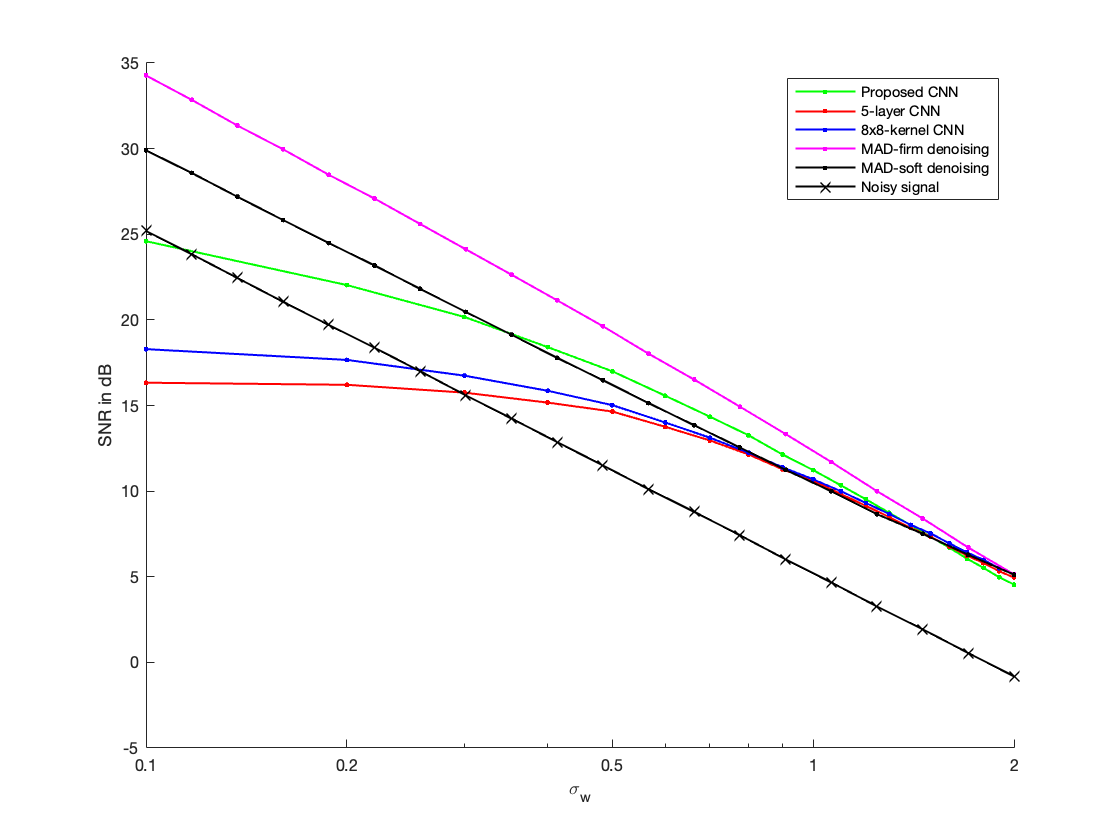

MSE_soft = sqrt(MSE_soft);
MSE_firm = sqrt(MSE_firm);

set_plot_defaults('on')

figure(25)
clf
% semilogx(sigma_set, SNR_1,'g.-', sigma_set, SNR_3,'r.-', sigma_set, SNR_4,'b.-', sigma_w_, SNR_x_hat, 'k.-',sigma_w_, SNR_y, 'kx-');
semilogx(sigma_set, SNR_1,'g.-', sigma_set, SNR_3,'r.-', sigma_set, SNR_4,'b.-', sigma_w_, SNR_x_firm, 'm.-', sigma_w_, SNR_x_soft, 'k.-',sigma_w_, SNR_y, 'kx-');
hold off;
% legend('Proposed CNN', '5-layer CNN', '8x8-kernel CNN', 'MAD-soft denoising', 'Noisy signal');
legend('Proposed CNN', '5-layer CNN', '8x8-kernel CNN', 'MAD-firm denoising', 'MAD-soft denoising', 'Noisy signal');
xlabel('\sigma_w')
ylabel('SNR in dB')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_w_) max(sigma_w_)])
box off

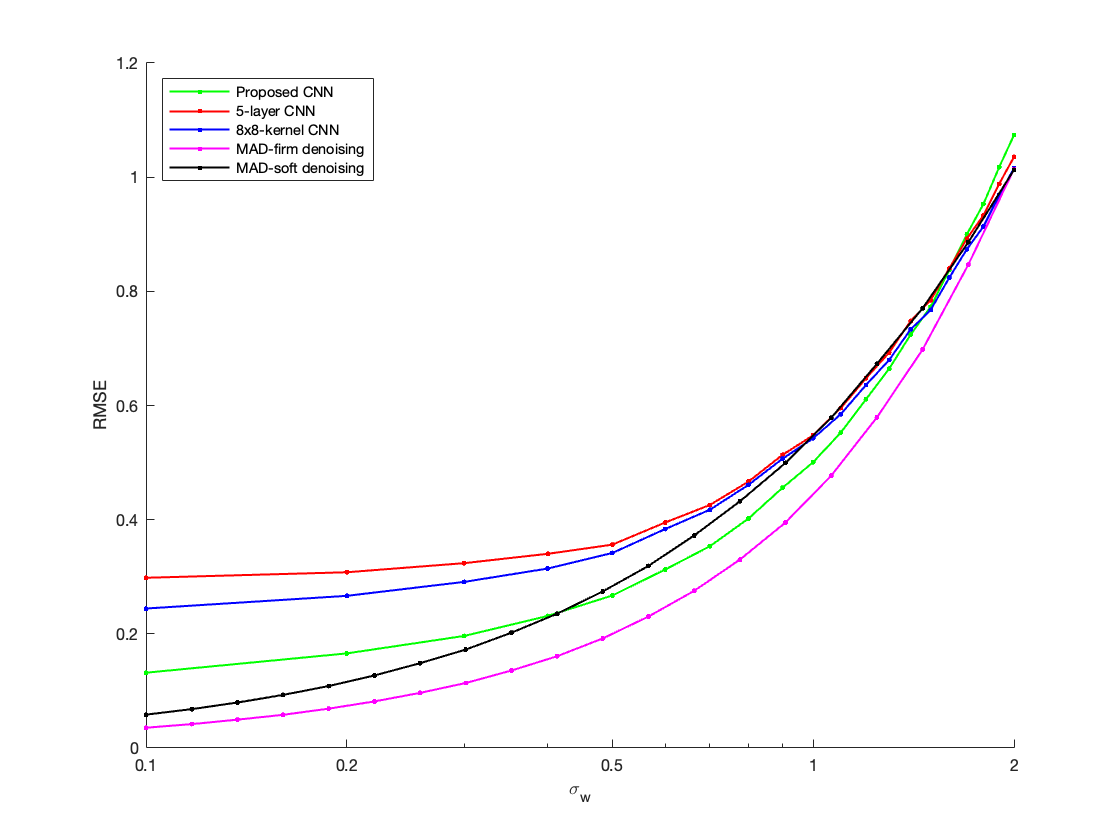


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/SNR_average

figure(26)
clf
% semilogx(sigma_set, MSE_1,'g.-', sigma_set, MSE_3,'r.-', sigma_set, MSE_4,'b.-', sigma_w_, MSE_mad,'k.-');
semilogx(sigma_set, MSE_1,'g.-', sigma_set, MSE_3,'r.-', sigma_set, MSE_4,'b.-', sigma_w_, MSE_firm,'m.-', sigma_w_, MSE_soft,'k.-');
hold off;
% legend('Proposed CNN', '5-layer CNN', '8x8-kernel CNN', 'MAD-soft denoising', 'Location','NorthWest');
legend('Proposed CNN', '5-layer CNN', '8x8-kernel CNN', 'MAD-firm denoising', 'MAD-soft denoising', 'Location','NorthWest');
xlabel('\sigma_w')
ylabel('RMSE')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_w_) max(sigma_w_)])
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/MSE_average

set_plot_defaults('off')


%% Create the comparison form for different methods.

num = 1000;
SNR_num1 = zeros(1,num);
MSE_num1 = zeros(1,num);
SNR_num3 = zeros(1,num);
MSE_num3 = zeros(1,num);
SNR_num4 = zeros(1,num);
MSE_num4 = zeros(1,num);
MSE_noise = zeros(1,num);
SNR_noise = zeros(1,num);

SNR_mad = zeros(1,num);
MSE_mad = zeros(1,num);


for j = 1:1:num

    sigma = 1.75;                   % change from 0.25 to 1.75
    K = ceil(50*rand()+25);
    groundtruth = zeros(1, N);
    index_random = randperm(N);
    index = index_random(1:K);
    groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
    ini_noise = sigma*randn(1,N);
    input = groundtruth + ini_noise;
    
    MSE_noise(j) = mean(ini_noise.^2);
    SNR_noise(j) = 10*log10(mean(groundtruth.^2)/MSE_noise(j));

    output = CNN(input, h1);
    noise = output - groundtruth;
    MSE_num1(j) = mean(noise.^2);
    SNR_num1(j) = 10*log10(mean(groundtruth.^2)/MSE_num1(j));

    output = CNN(input, h3);
    noise = output - groundtruth;
    MSE_num3(j) = mean(noise.^2);
    SNR_num3(j) = 10*log10(mean(groundtruth.^2)/MSE_num3(j));

    output = CNN(input, h4);
    noise = output - groundtruth;
    MSE_num4(j) = mean(noise.^2);
    SNR_num4(j) = 10*log10(mean(groundtruth.^2)/MSE_num4(j));
    
    output = soft_MAD(input);
    noise = output - groundtruth;
    MSE_mad(j) = mean(noise.^2);
    SNR_mad(j) = 10*log10(mean(groundtruth.^2)/MSE_mad(j));

end

SNR_1 = mean(SNR_num1)

SNR_1 = 5.8395

MSE_1 = mean(MSE_num1)

MSE_1 = 0.8611

SNR_3 = mean(SNR_num3)

SNR_3 = 6.0348

MSE_3 = mean(MSE_num3)

MSE_3 = 0.8409

SNR_4 = mean(SNR_num4)

SNR_4 = 6.2260

MSE_4 = mean(MSE_num4)

MSE_4 = 0.8054

noiseSNR = mean(SNR_noise)

noiseSNR = 0.2369

noiseMSE = mean(MSE_noise)

noiseMSE = 3.0612


madSNR = mean(SNR_mad)

madSNR = 6.0027

madMSE = mean(MSE_mad)

madMSE = 0.8346

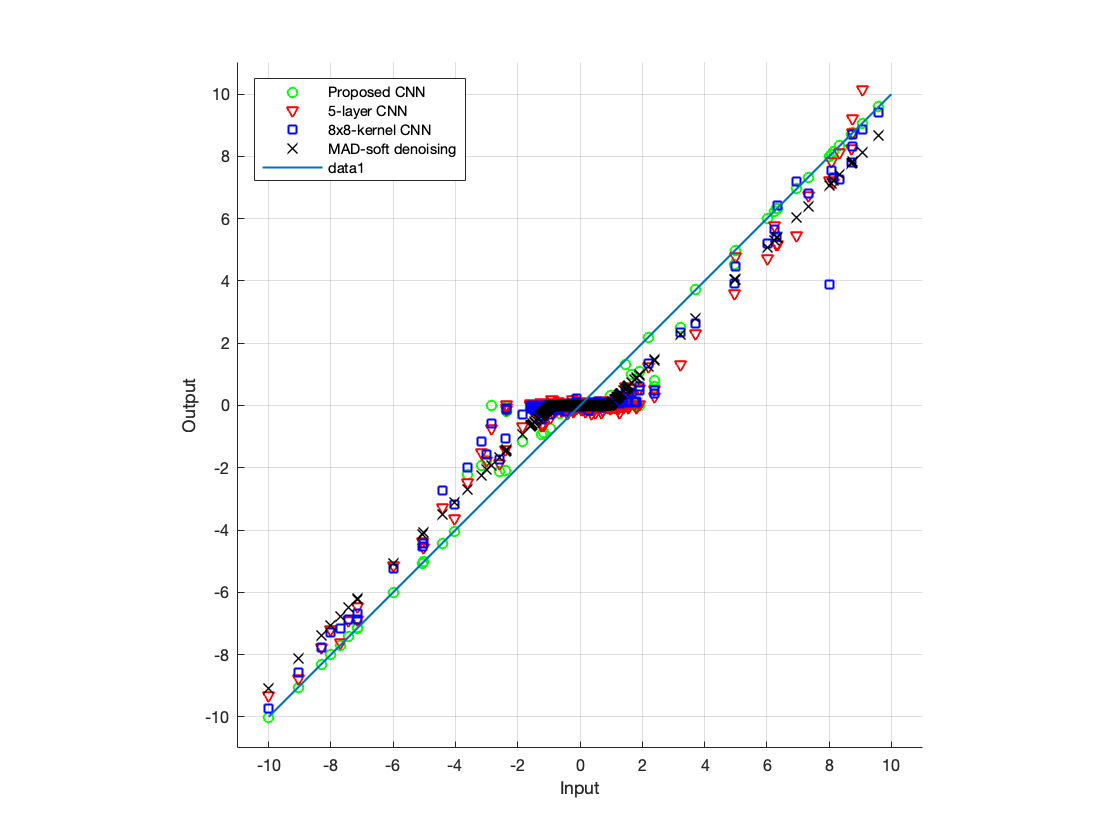

%% Plot output v.s. input for all the methods.

set_plot_defaults('on')

N = 500;
K = 50;
sigma = 0.75;
groundtruth = zeros(1, N);
index_random = randperm(N);
index = index_random(1:K);
groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
ini_noise = sigma*randn(1,N);
input = groundtruth + ini_noise;

output1 = CNN(input,h1);
output3 = CNN(input,h3);
output4 = CNN(input,h4);
output_mad = soft_MAD(input);

figure(27)
plot(input, output1, 'go', input, output3, 'rv', input, output4, 'bs', input, output_mad, 'kx', 'MarkerSize',5)
hold on
legend('Proposed CNN', '5-layer CNN', '8x8-kernel CNN', 'MAD-soft denoising', 'Location', 'NorthWest');
xlabel('Input')
ylabel('Output')
grid
axis equal square
line([-10 10], [-10 10])
hold off
xlim([-11,11])
ylim([-11,11])
box off


% set(gcf, 'PaperPosition', [1 1 14 14])

% print -depsc figures/compare

set_plot_defaults('off')


%% Adaptive version

threshold1 = 2.61;
threshold2 = 5.26;
rho = 1;                % rho is the ratio between output and input signal.
l = 37;            % l is the length of the filters in the second layer.
training_sigma = 2;     % The standard deviation of the Gaussian noise in the training data is between 0 and training_sigma.
training_num = 20000;   % training_num is the number of the training signals.
training_type = 1;      % 1 means Uniform and 2 means Gaussian.
istrain_flag = false;   % istrain_flag can determine if training a new CNN or directly using the trained parameters.
h = create_denoiser(l,rho,threshold1,threshold2,training_type,istrain_flag);

N = 500;
K = 50;
num = 50;
ratio = K/N;                          % sparsity level
sigma_x = 10.0;                     % Gaussian standard deviation
l = 37;

[sigma_w_, SNR_x_soft, SNR_x_firm, SNR_y, MSE_firm, MSE_soft] = sparse_denoise_MAD_calculate_SNR(N, ratio, sigma_x);

progress = 0.050000
progress = 0.100000
progress = 0.150000
progress = 0.200000
progress = 0.250000
progress = 0.300000
progress = 0.350000
progress = 0.400000
progress = 0.450000
progress = 0.500000
progress = 0.550000
progress = 0.600000
progress = 0.650000
progress = 0.700000
progress = 0.750000
progress = 0.800000
progress = 0.850000
progress = 0.900000
progress = 0.950000
progress = 1.000000


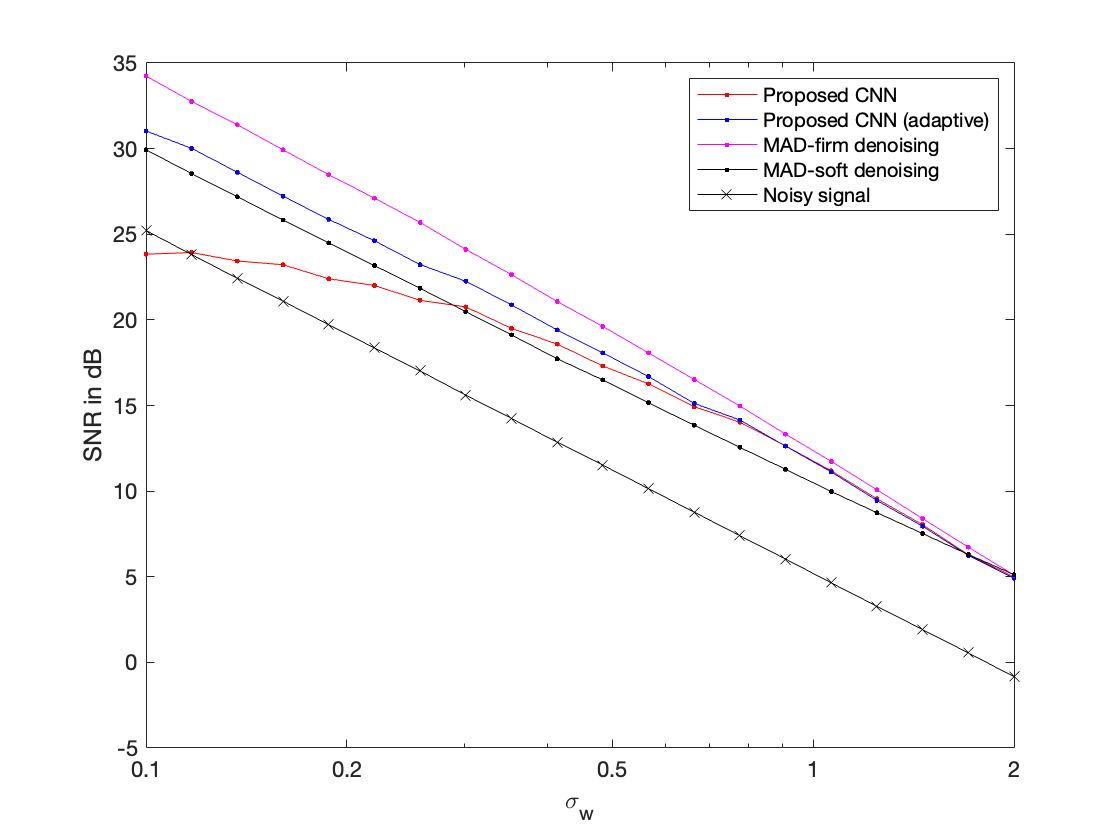

MSE_soft = sqrt(MSE_soft);
MSE_firm = sqrt(MSE_firm);

ratio = 1;
% t1 = 2.61;
% t2 = 5.26;
MSE_CNN = zeros(1,length(sigma_w_));
SNR_CNN = zeros(1,length(sigma_w_));
SNR_ori = zeros(1,length(sigma_w_));

for i = 1:1:length(sigma_w_)
    sigma = sigma_w_(i);
    MSE_CNN_epo = zeros(1,num);
    SNR_CNN_epo = zeros(1,num);
    SNR_ori_epo = zeros(1,num);
    for j = 1:1:num

        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
        input = groundtruth + sigma*randn(1,N);
        t1 = 2*1.4826*median(abs(input));
        t2 = 4.4*1.4826*median(abs(input));
        h1 = adaptive_denoiser(input,l,ratio,t1,t2);
        output = CNN(input,h1);
        MSE_CNN_epo(j) = mean((output-groundtruth).^2);
        SNR_CNN_epo(j) = 10*log10(mean(groundtruth.^2)/MSE_CNN_epo(j));
        output = CNN(input,h);
%         MSE_CNN_epo(j) = mean((output-groundtruth).^2);
        SNR_ori_epo(j) = 10*log10(mean(groundtruth.^2)/mean((output-groundtruth).^2));

    end
    MSE_CNN(i) = sqrt(mean(MSE_CNN_epo));
    SNR_CNN(i) = mean(SNR_CNN_epo);
    SNR_ori(i) = mean(SNR_ori_epo);
    
end

figure(28)
semilogx(sigma_w_, SNR_ori, 'r.-', sigma_w_, SNR_CNN, 'b.-', sigma_w_, SNR_x_firm, 'm.-', sigma_w_, SNR_x_soft, 'k.-',sigma_w_, SNR_y, 'kx-');
hold off;
legend('Proposed CNN', 'Proposed CNN (adaptive)', 'MAD-firm denoising', 'MAD-soft denoising', 'Noisy signal');
xlabel('\sigma_w')
ylabel('SNR in dB')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_w_) max(sigma_w_)])